## Aim:  

- To understand the need for short term processing of speech.

- To compute short term energy and study its significance.

- To compute short term zero crossing rate and study its significance.

- To compute short term autocorrelation and study its significance.

**Theory:**

Short term analysis of speech is very important, this is because speech is a quasi stationary signal hence to study its properties we need to consider small frames of this signal.

**Step 0:** To record the phrase 'SPEECH SIGNAL' and trim the silence periods.

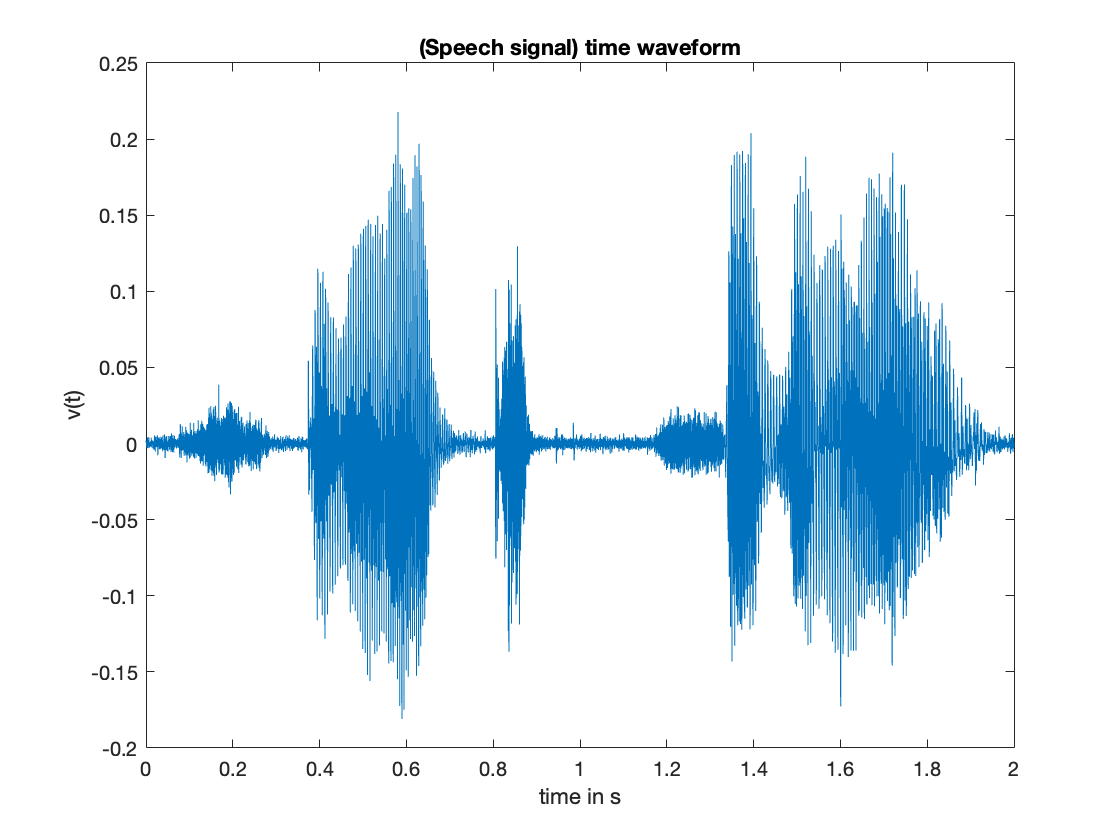

% Full audio
[y_full,Fs] = audioread("Lab6.wav");

% Trimming the audio
y = y_full(Fs*0.75:Fs*2.75);

% Time duration of the given audio file 
time_duration = length(y)/Fs;

% Generating the time axis
t = 0 : 1/Fs : time_duration - 1/Fs;

% Time domain plotting
plot(t,y);
title("(Speech signal) time waveform");
xlabel("time in s");
ylabel("v(t)");

**Part A: **

(i) To compute and plot short term energy for frame size = 20ms and frame shift = 10ms

(ii) To compute short term energy for multiple frame shifts and frame sizes.

**Theory:**

The energies of different frames in the same speech signal are not the same. Hence short term energy (energy as a function of frames) is an importat parameter to study different speech sounds.

More specifically the voiced sounds have higher energy as compared unvoiced sounds. We can use short term energy to identify voiced, unvoiced and silence regions of the signal.

The short term energy of a signal is given by:


$$E_t \;=\textrm{sum}\left(s\left(n\right)\right)\;\textrm{for}\;n=0\;\textrm{to}\;\textrm{frame}\;\textrm{size}$$


**Procedure:**

- We will use the STE function

- It takes the speech signal , frame size and frame shift as input (both in term of ms), and gives the ste plot.

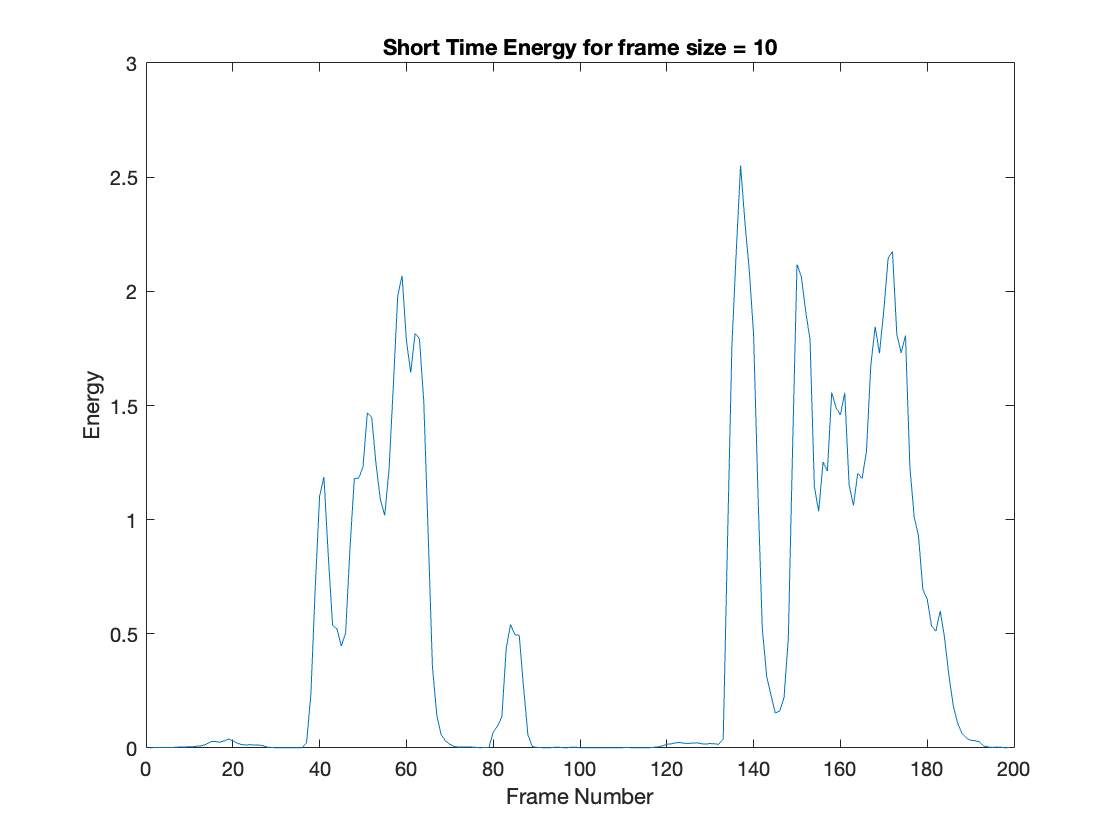

STE(y,Fs,20,10, "10");

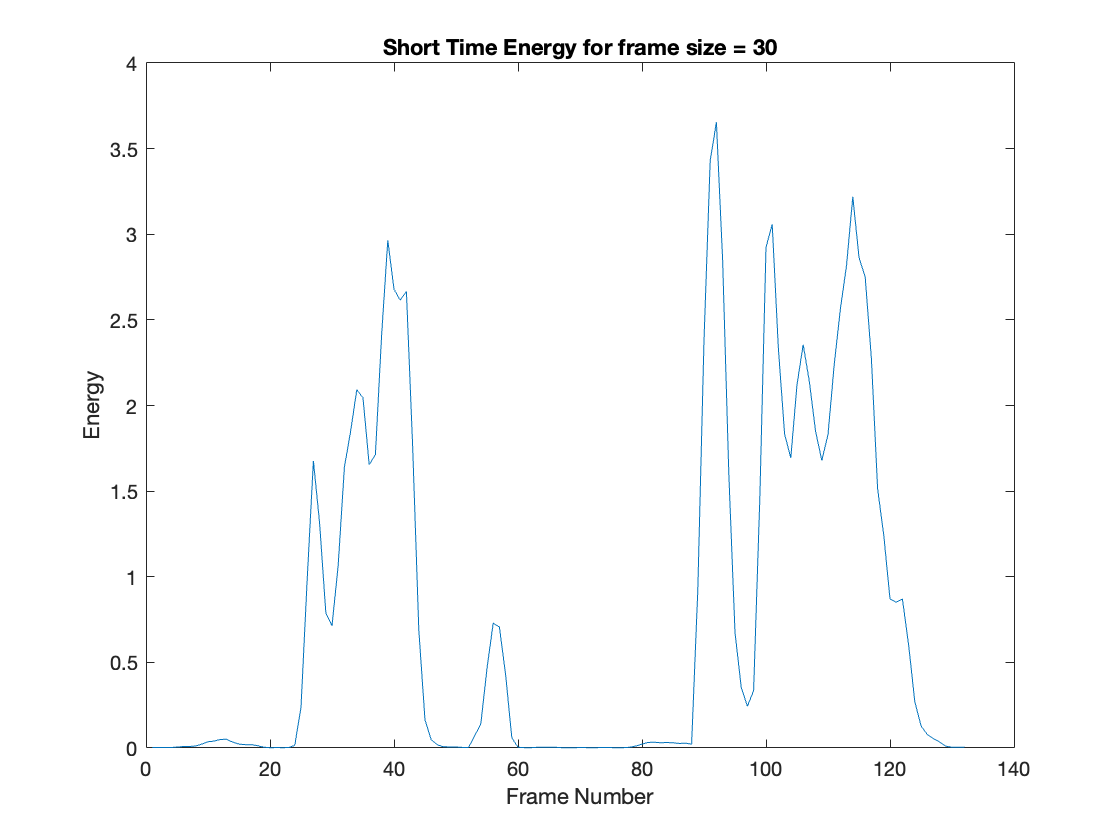

STE(y,Fs,30,15, "30");

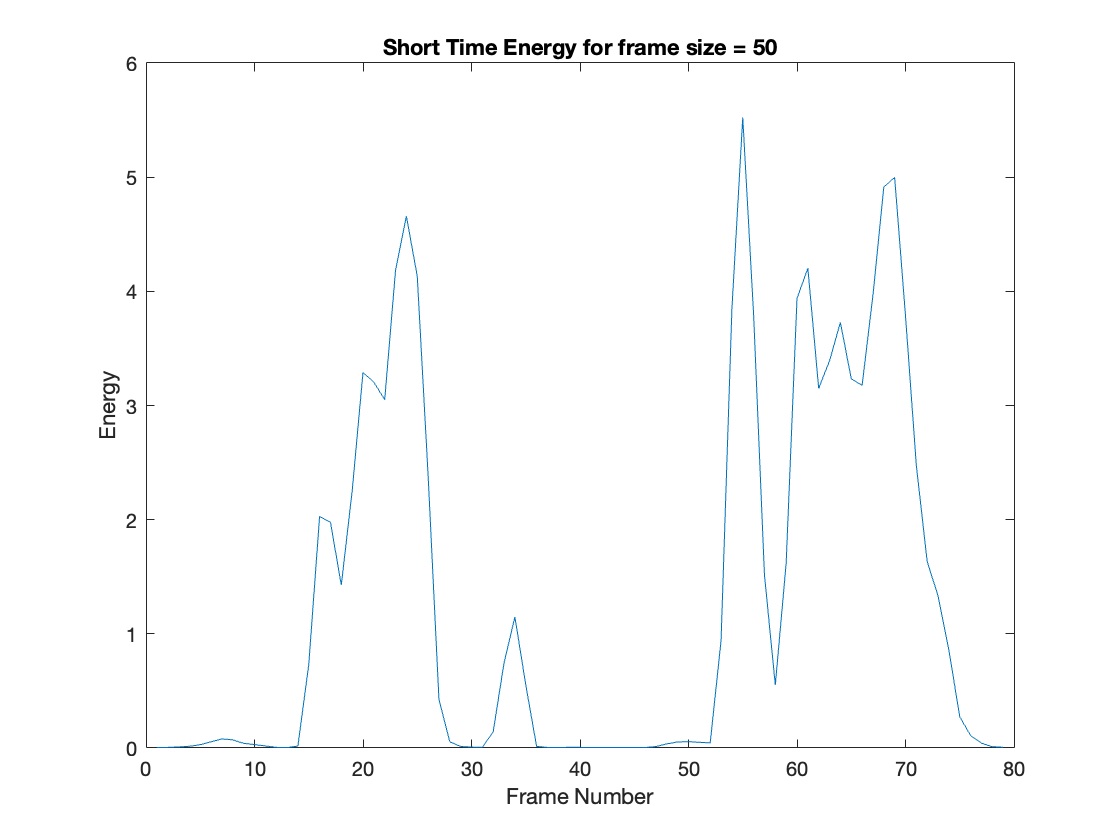

STE(y,Fs,50,25, "50");

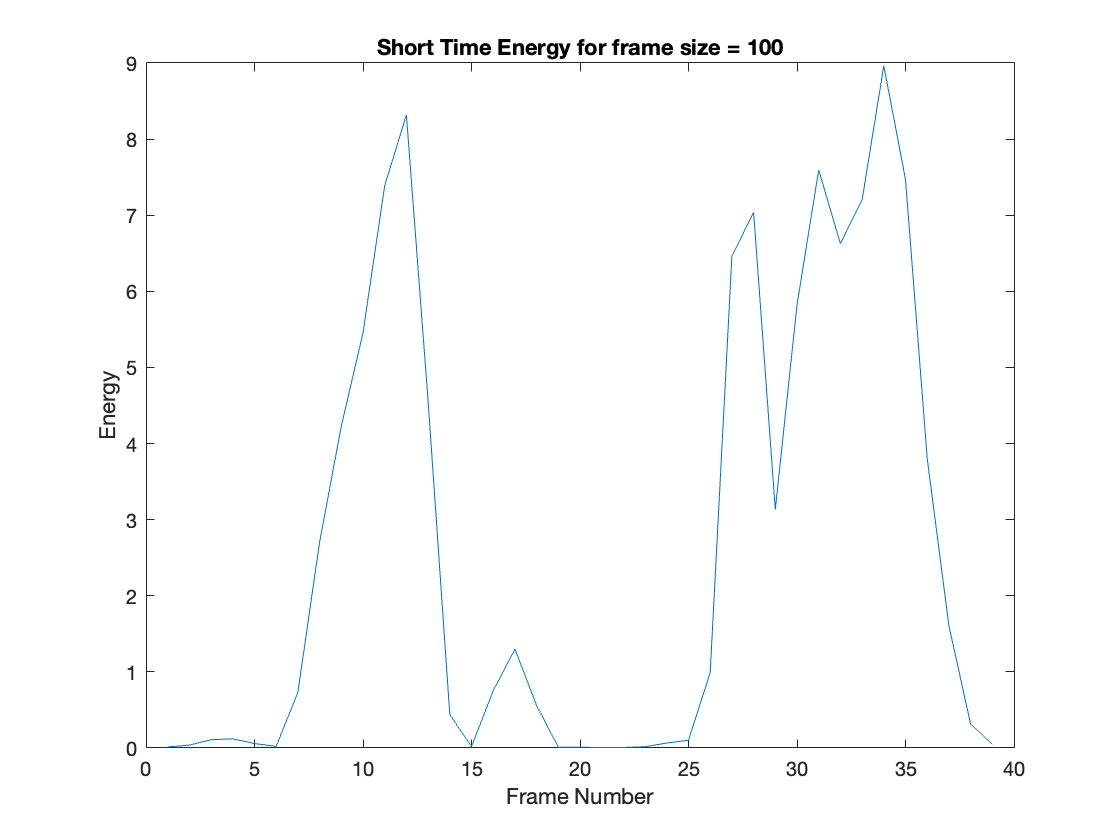

STE(y,Fs,100,50, "100");

**Observations:**

- As we increase the window size we can see that the resolution of the STE decreases.

- With a smaller window we can see exact intervals in which voiced sounds are present.

- In larger window size we are unable to see exact intervals of voiced sounds.

**Conclusion: **Preffered frame size is 20 ms

**Part B:**

(i) To compute short term zero crossing rate for frame size = 20ms and frame shift = 10ms.

(ii) Compute the same for different frame shifts and frame sizes.

**Theory:**

As the name suggests zero crossing rate gives us the information of how many times the signal crosses the time axis.If the ZCR of a signal is high it means that the nuber of zero crossings is very high. 

As the zero crossings are high we can say that the signal may contain high frequency components.

 Conversely we can say that if ZCR is low the signal may contain low frequency components. Thus ZCR gives an indirect information about the frequency content of the signal.

**Procedure:**

- We will use the ZCR function

- It takes the speech signal , frame size and frame shift as input (both in term of ms), and gives the zcr plot.

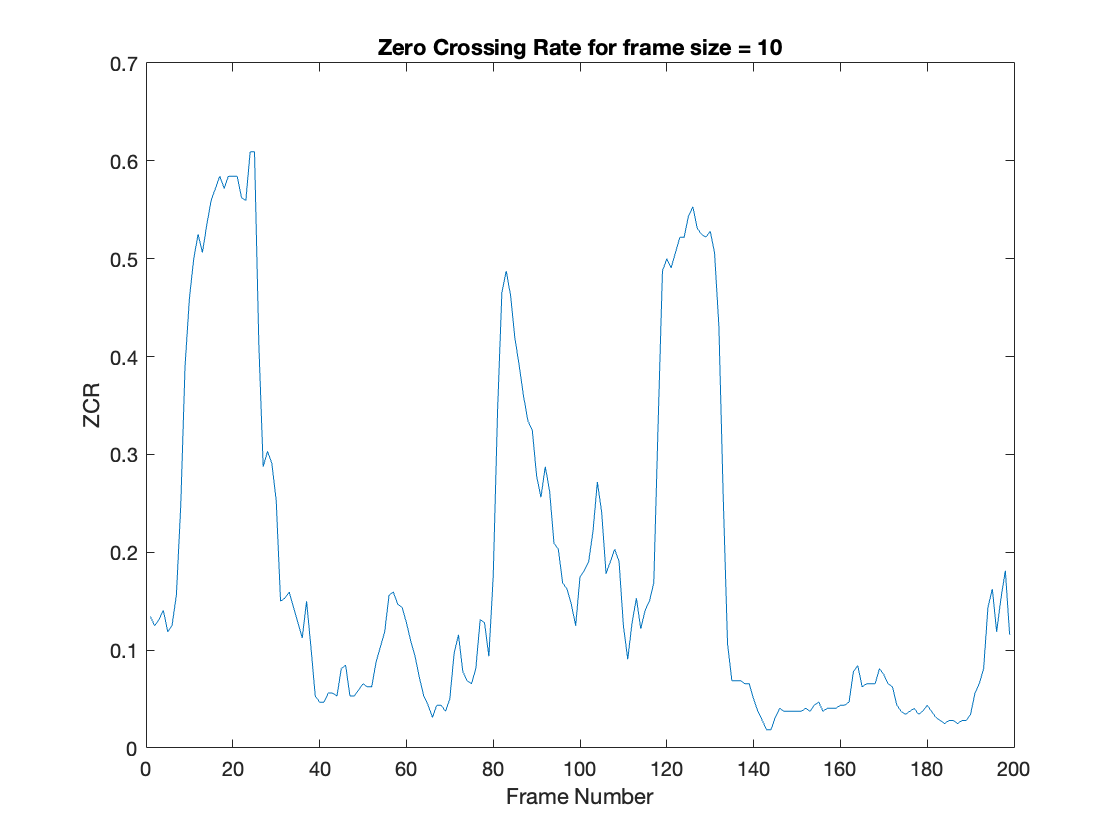

ZCR(y,Fs,20,10, "10");

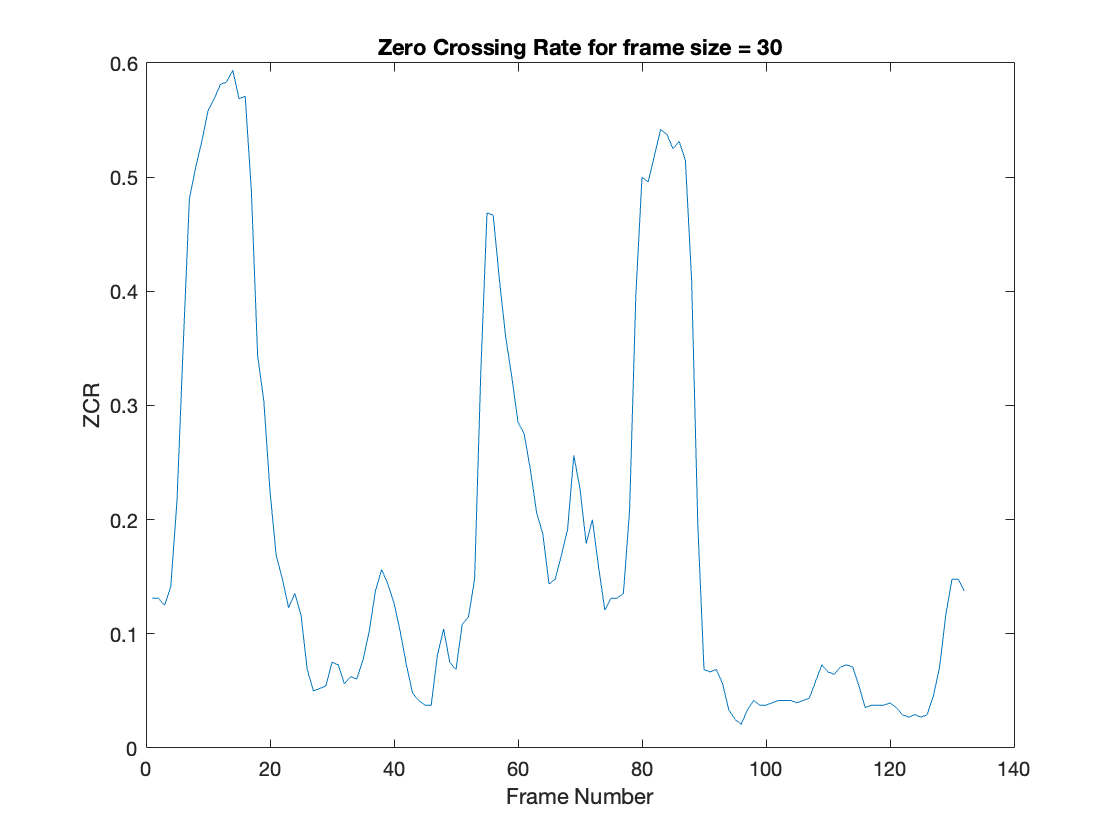

ZCR(y,Fs,30,15, "30");

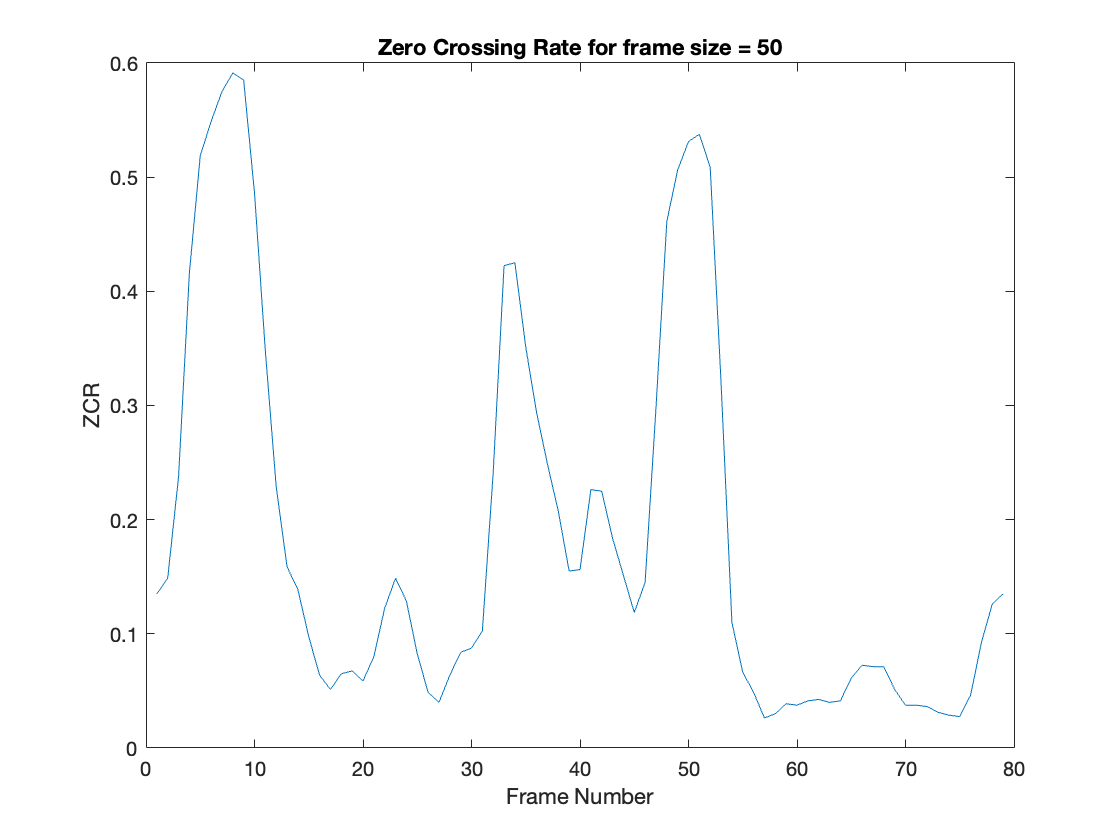

ZCR(y,Fs,50,25, "50");

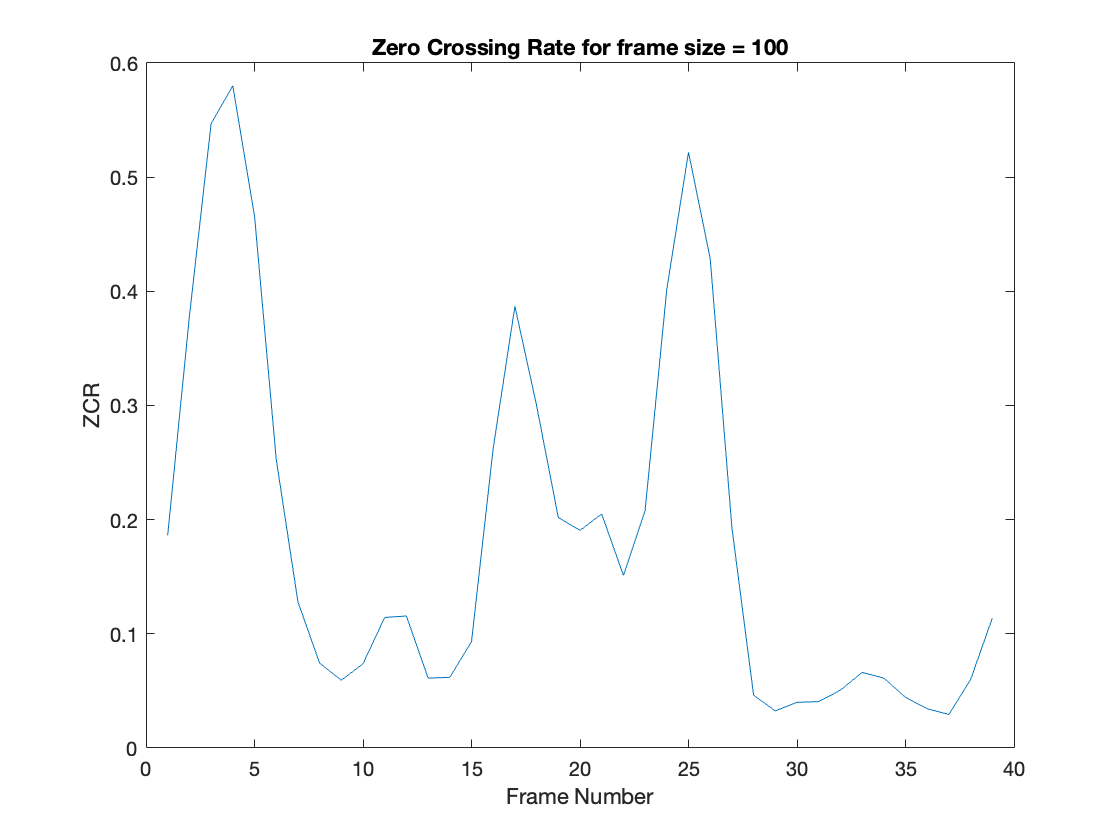

ZCR(y,Fs,100,50, "100");

**Observations:**

The  ZCR behaves similar to STE as we increase the frame size

- As we increase the window size we can see that the resolution of the zcr decreases.

- With a smaller window we can see exact intervals in which unvoiced sounds are present.

- In larger window size we are unable to see exact intervals of unvoiced sounds.

**Conclusion: **Preffered frame size is 20 ms

**Part C:**

(i) Extract 10ms, 20ms, 30ms, 50ms and 100ms windows form the sound /ii/ and /s/.

(ii)Compute autocorrelation function for the extracted frames.

(iii)Repeat the same

**Theory:**

As the name suggests, autocorrelation is the correlation of the signal with a shifted version of itself.

Autocorrelation is a useful property for analysis of the speech signal in time domain. Correlation is defined as the mutual relationship between or connection between two entities. I

n a periodic signal if we autocorrelate a signal with it’s T (T is the period of the signal) shifted version of itself, we see that the autocorrelation value is high, as the two quantities that are being correlated are equal, 

hence Autocorrelation is used for determining the time period of the periodic segments of a speech signal.

Autocorrelation is given by :  $R_k =\left(s_i {\mathrm{xs}}_{i+k} \right)\;\mathrm{for}\;i=1\;\mathrm{to}\;N-k-1$  

Here ‘k’ is the shift, N is the length of the frame and rk is the autocorrelation for the given shift ‘k’.

**Procedure:**

(i) Extract segments for sounds /ii/ and /s/ with the specified lengths.

(ii)Pass these segments to AutoCorrPlot()  it takes the frame as input and gives the plot of auto correlation as output, this function uses AutoCorr() which computes the auto correlation function.

% Extracting small windows of the  sounds /ii/ and /s/

% 1) For rectangular window
y_s10 = y(Fs*0.17:Fs*0.18);
y_s20 = y(Fs*0.165:Fs*0.185);
y_s30 = y(Fs*0.16:Fs*0.19);
y_s50 = y(Fs*0.15:Fs*0.2);
y_s100 = y(Fs*0.125:Fs*0.225);

y_ii10 = y(Fs*0.495:Fs*0.505);
y_ii20 = y(Fs*0.49:Fs*0.51);
y_ii30 = y(Fs*0.485:Fs*0.515);
y_ii50 = y(Fs*0.475:Fs*0.525);
y_ii100 = y(Fs*0.45:Fs*0.55);

**Auto correlation plots using Rectangular window**

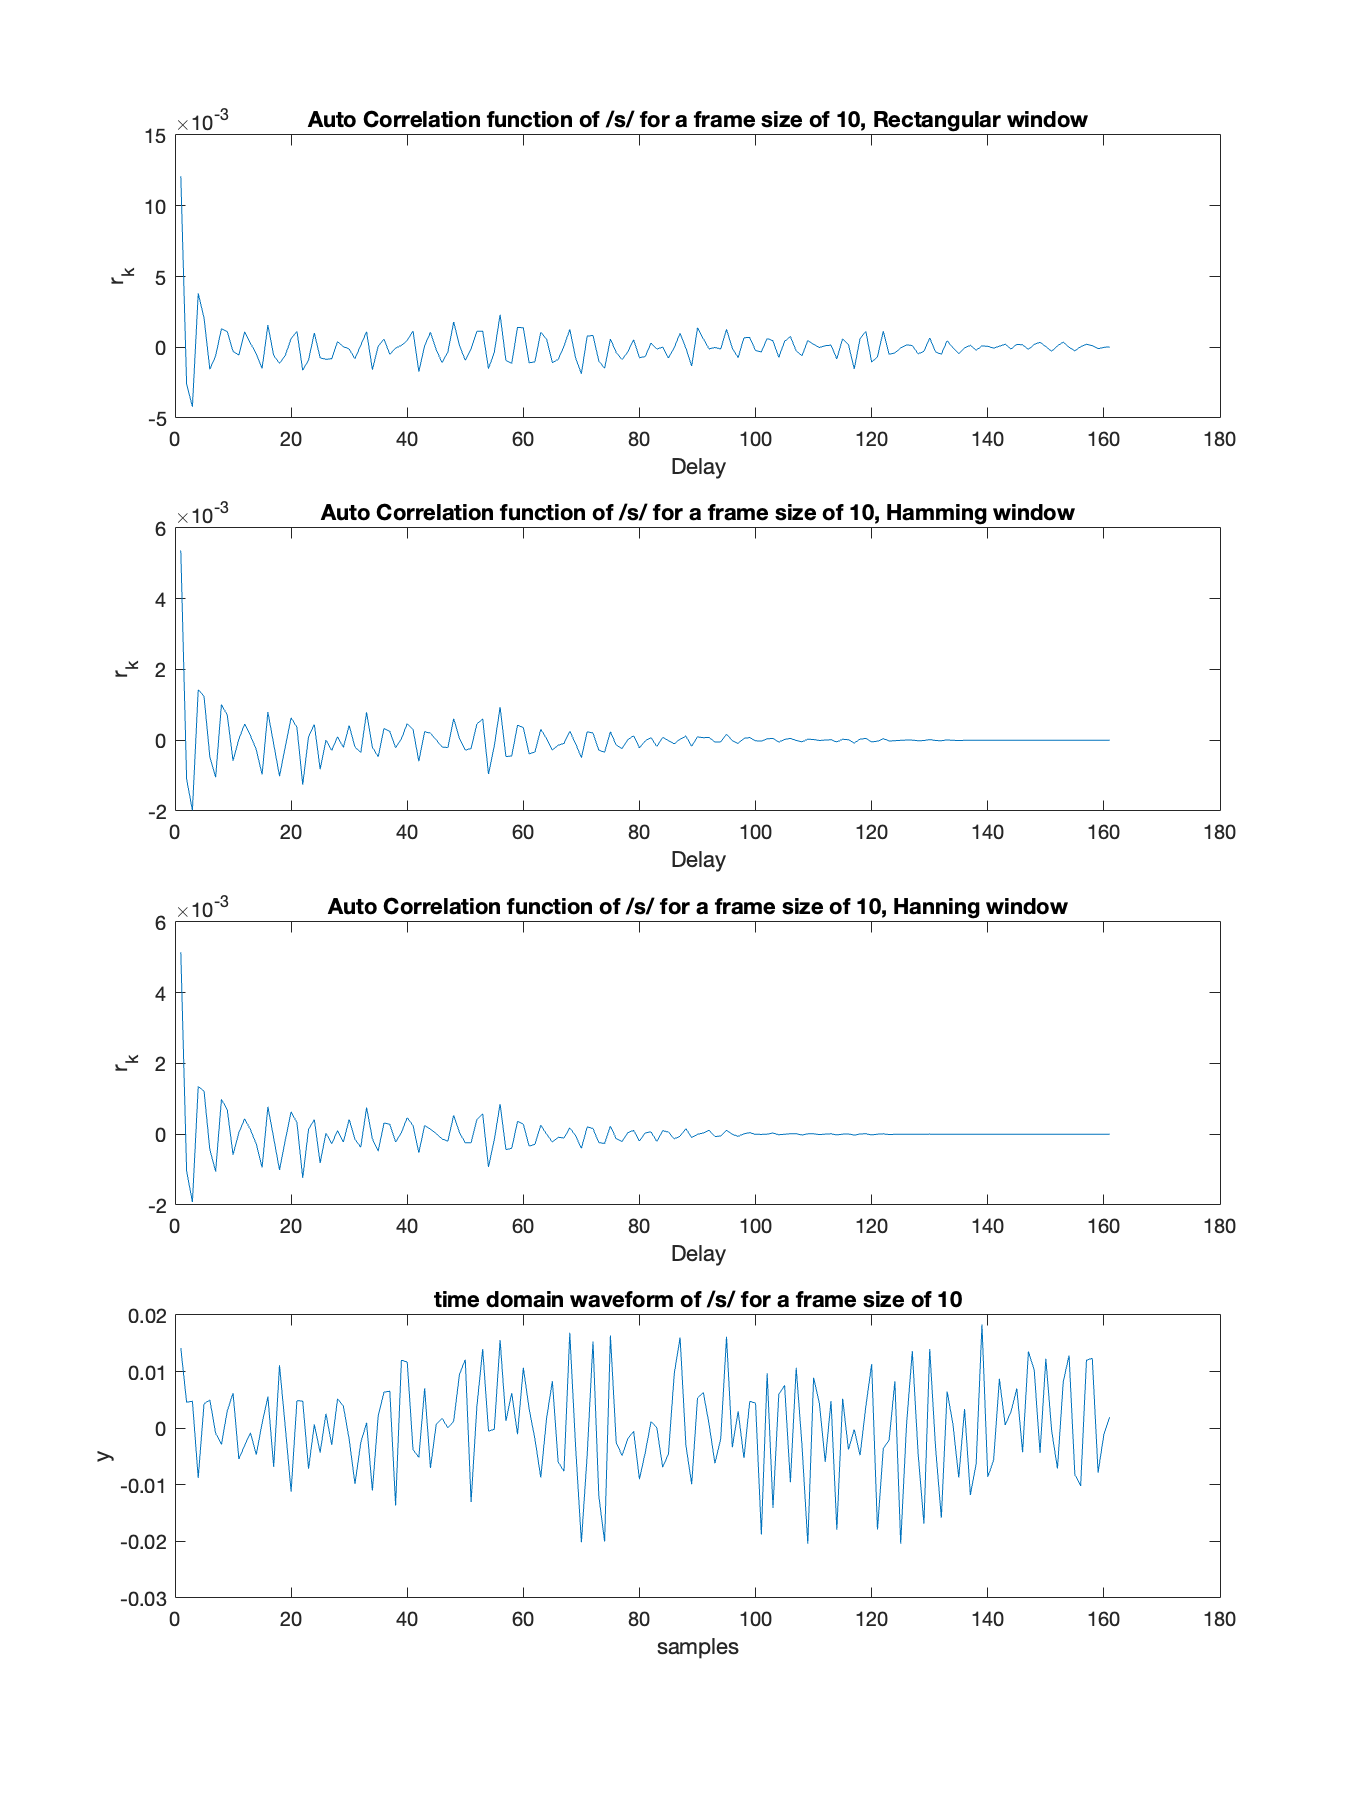

AutoCorrPlot(y_s10 , "/s/", "10");

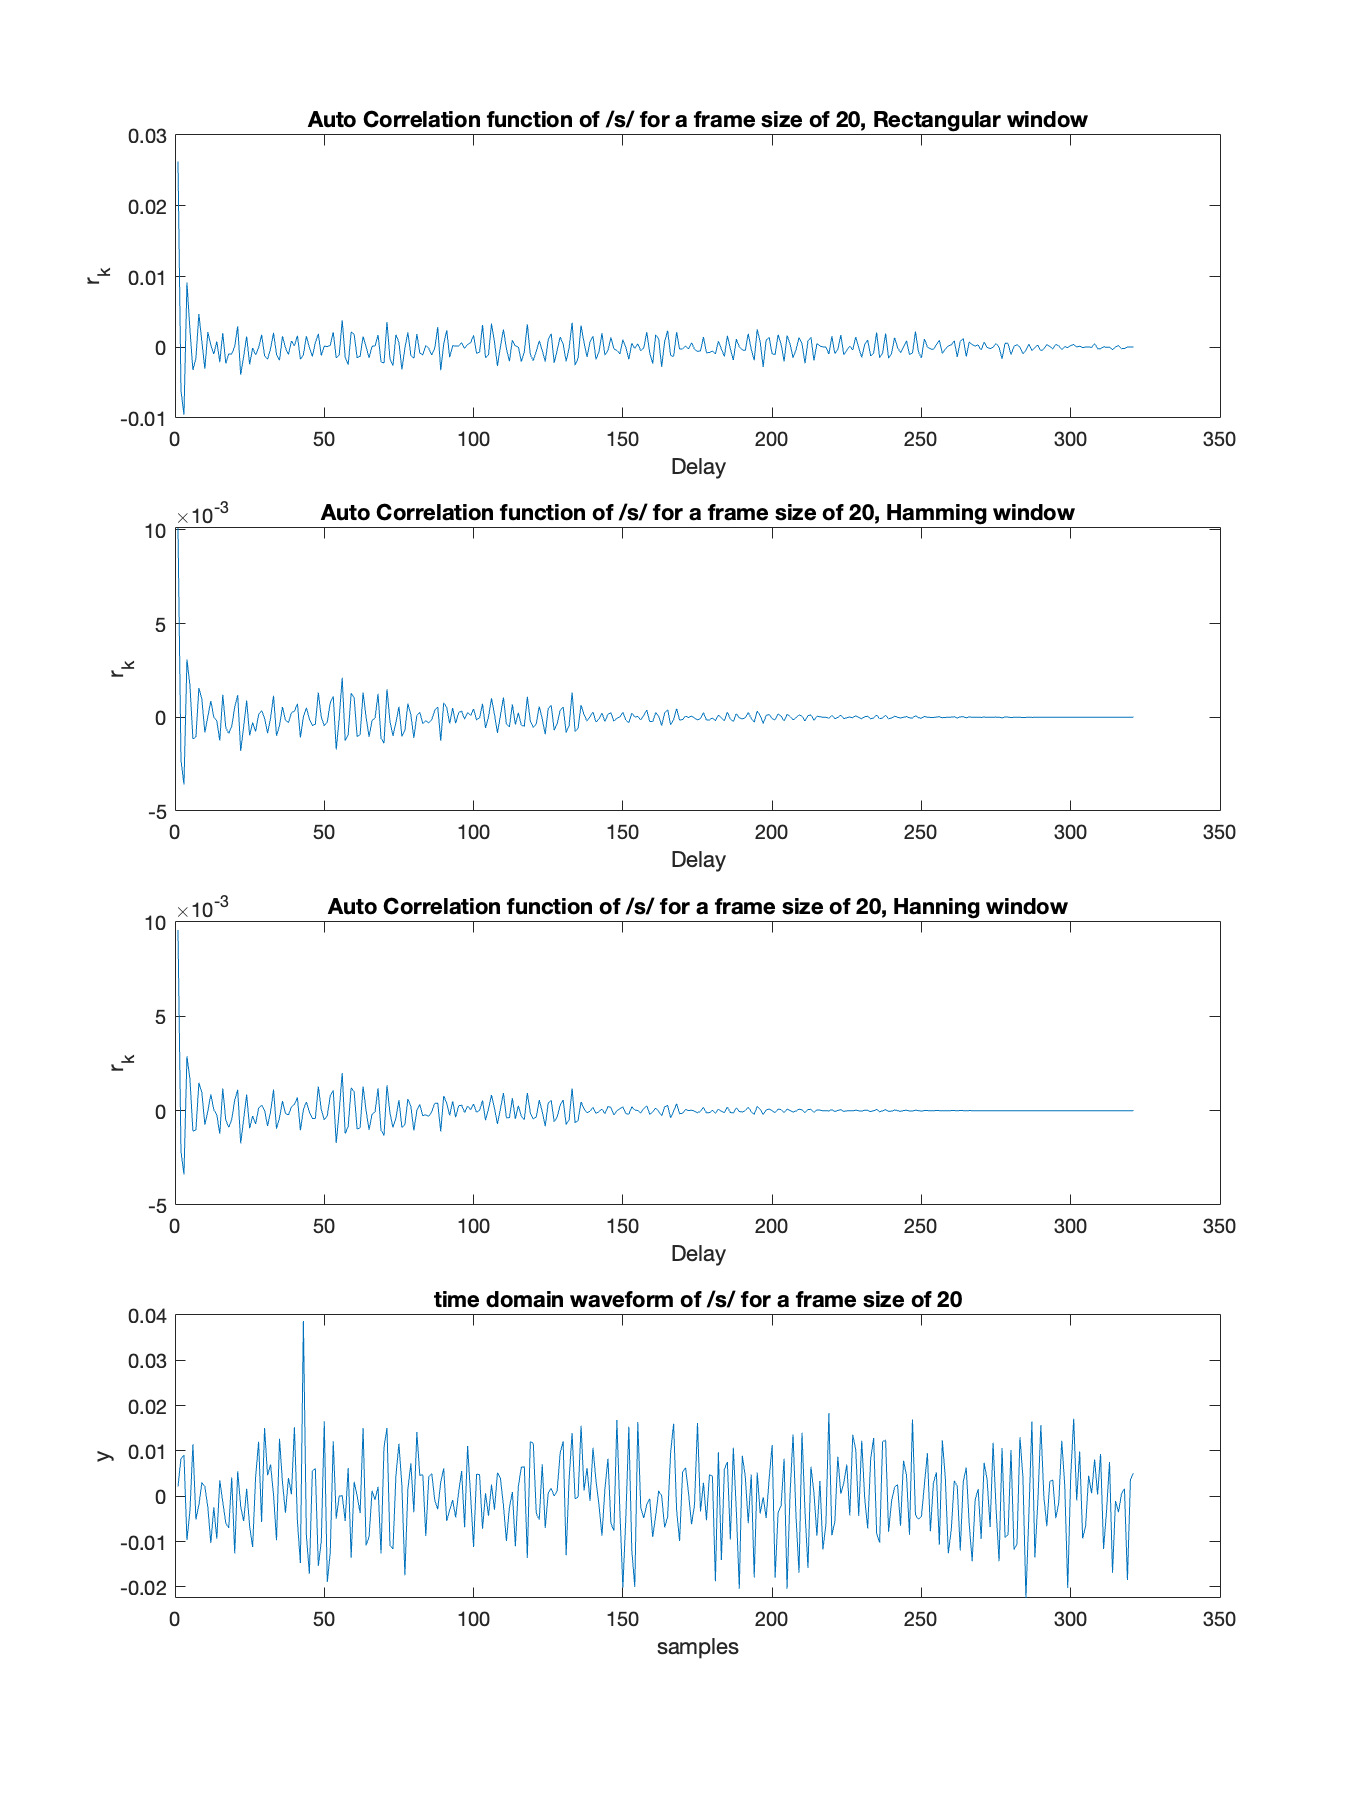

AutoCorrPlot(y_s20 , "/s/", "20");

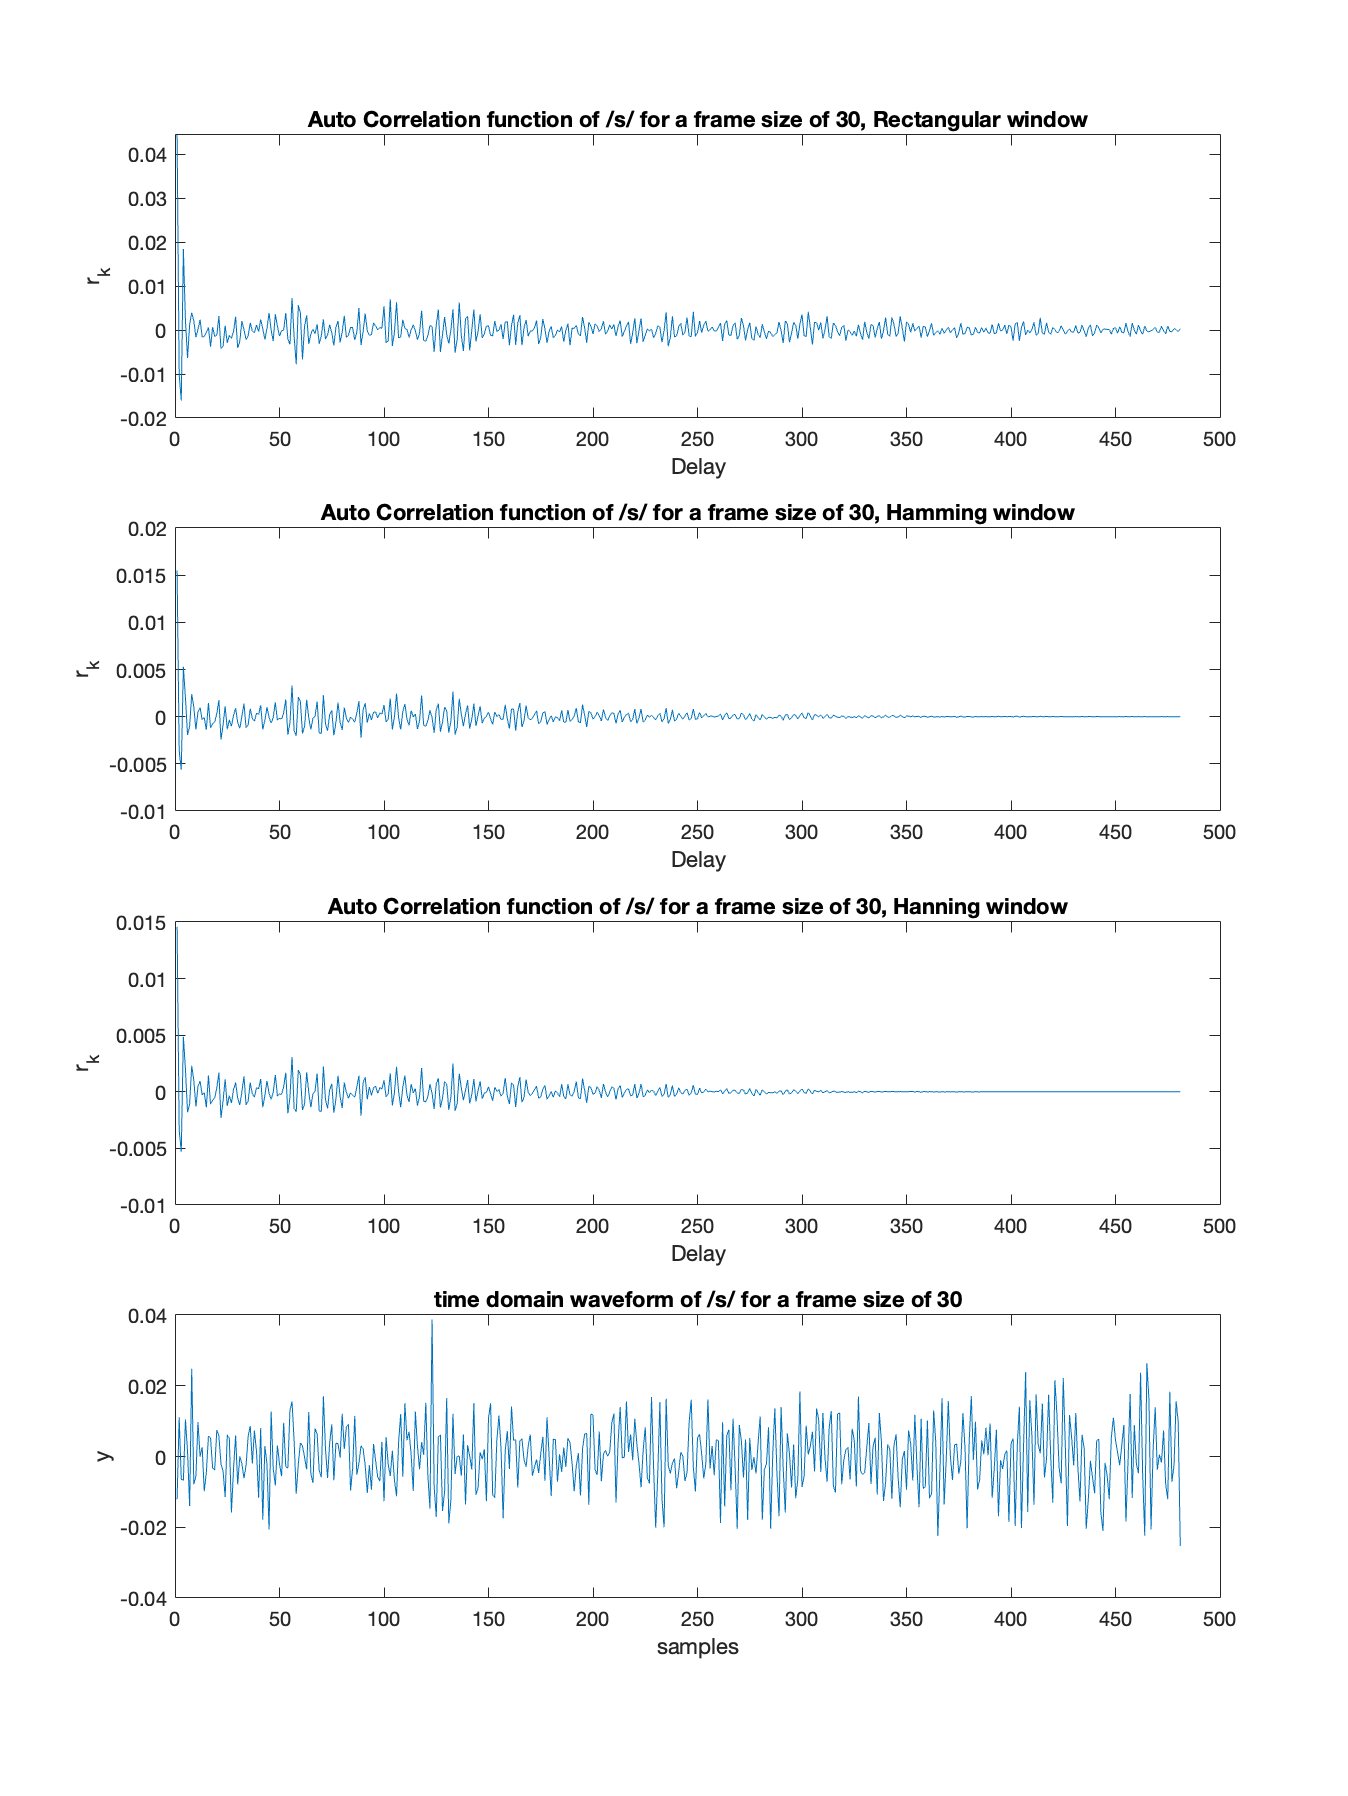

AutoCorrPlot(y_s30 , "/s/", "30");

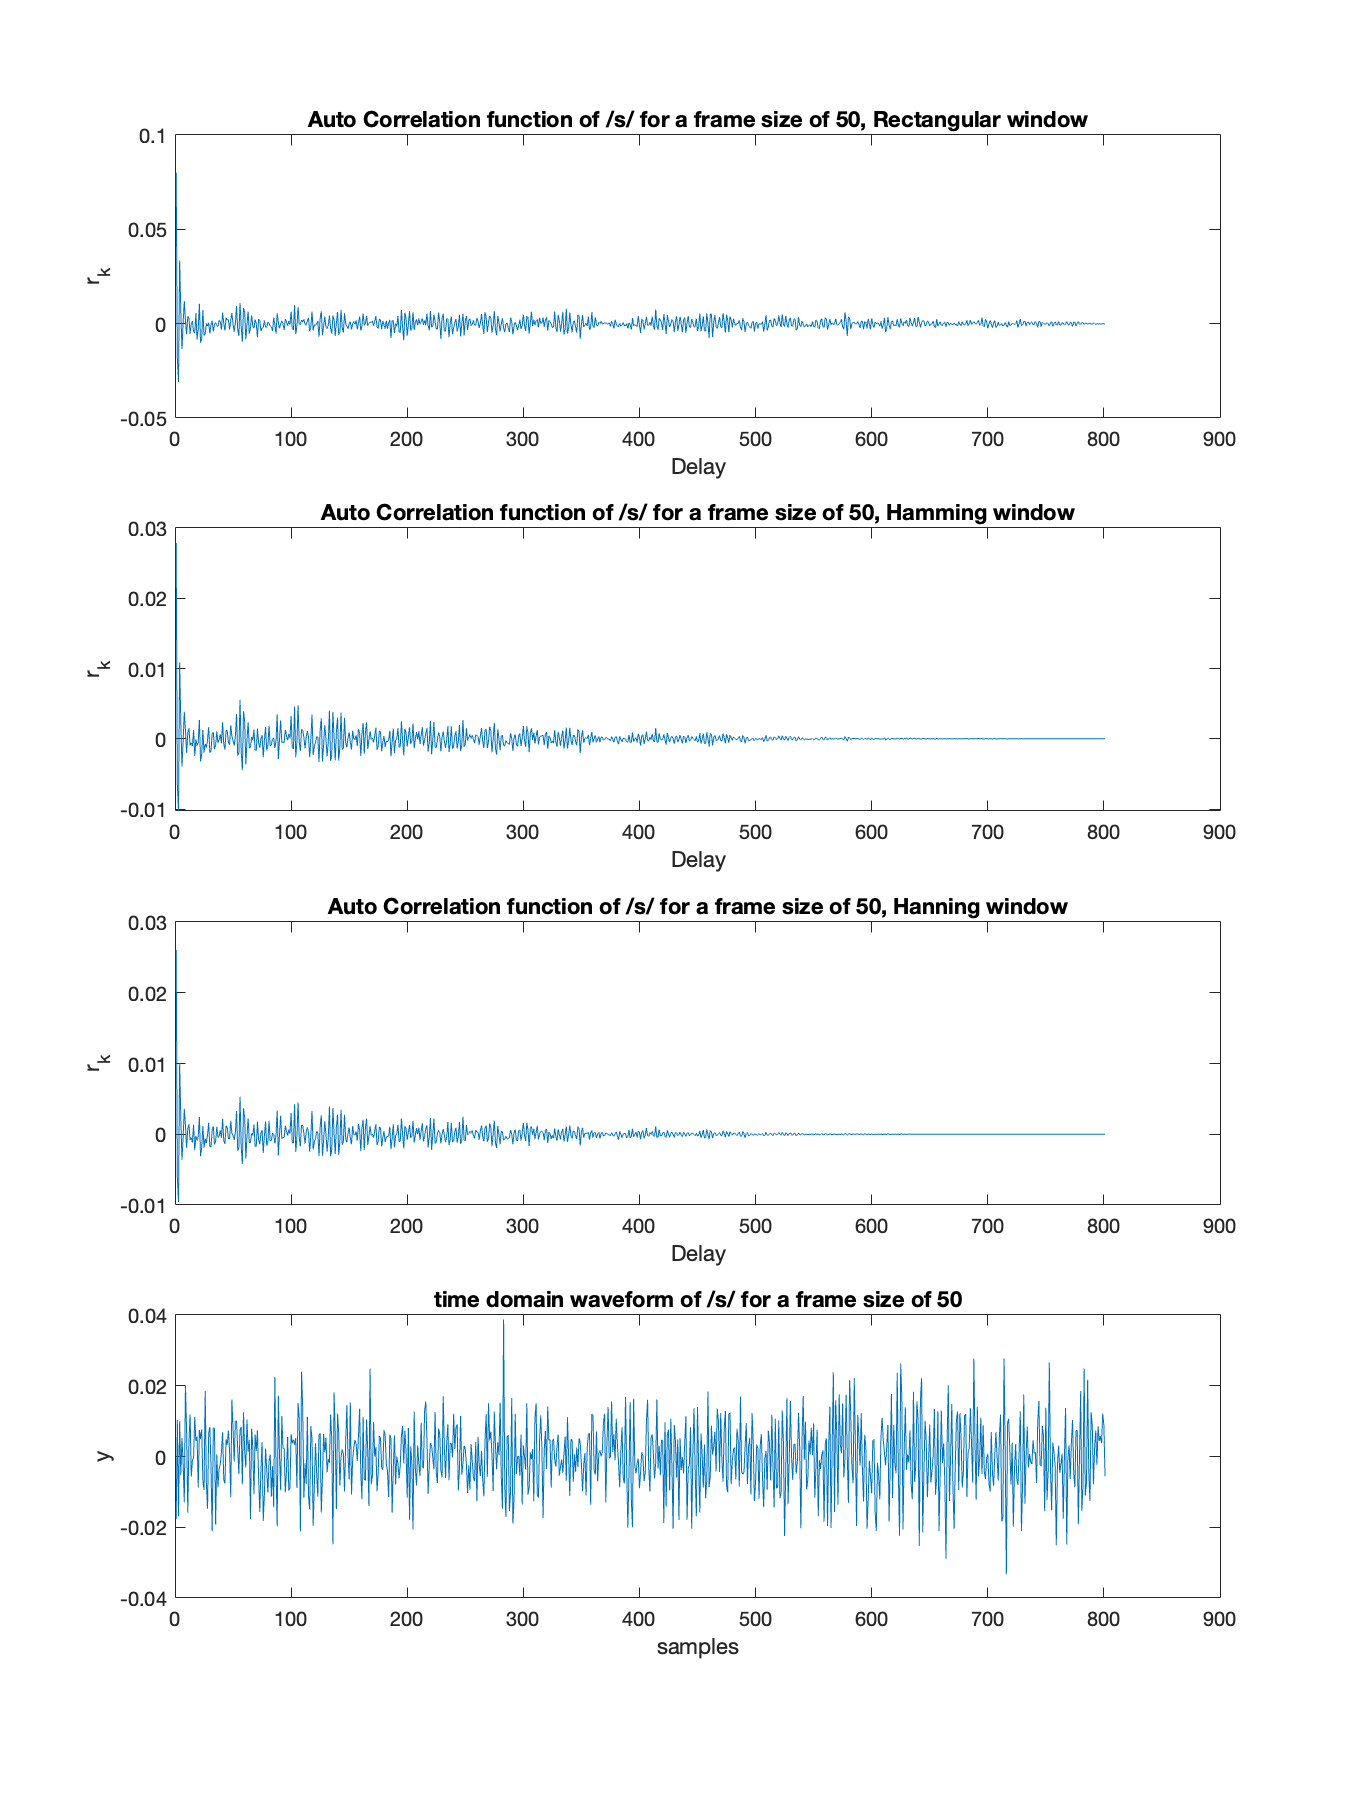

AutoCorrPlot(y_s50 , "/s/", "50");

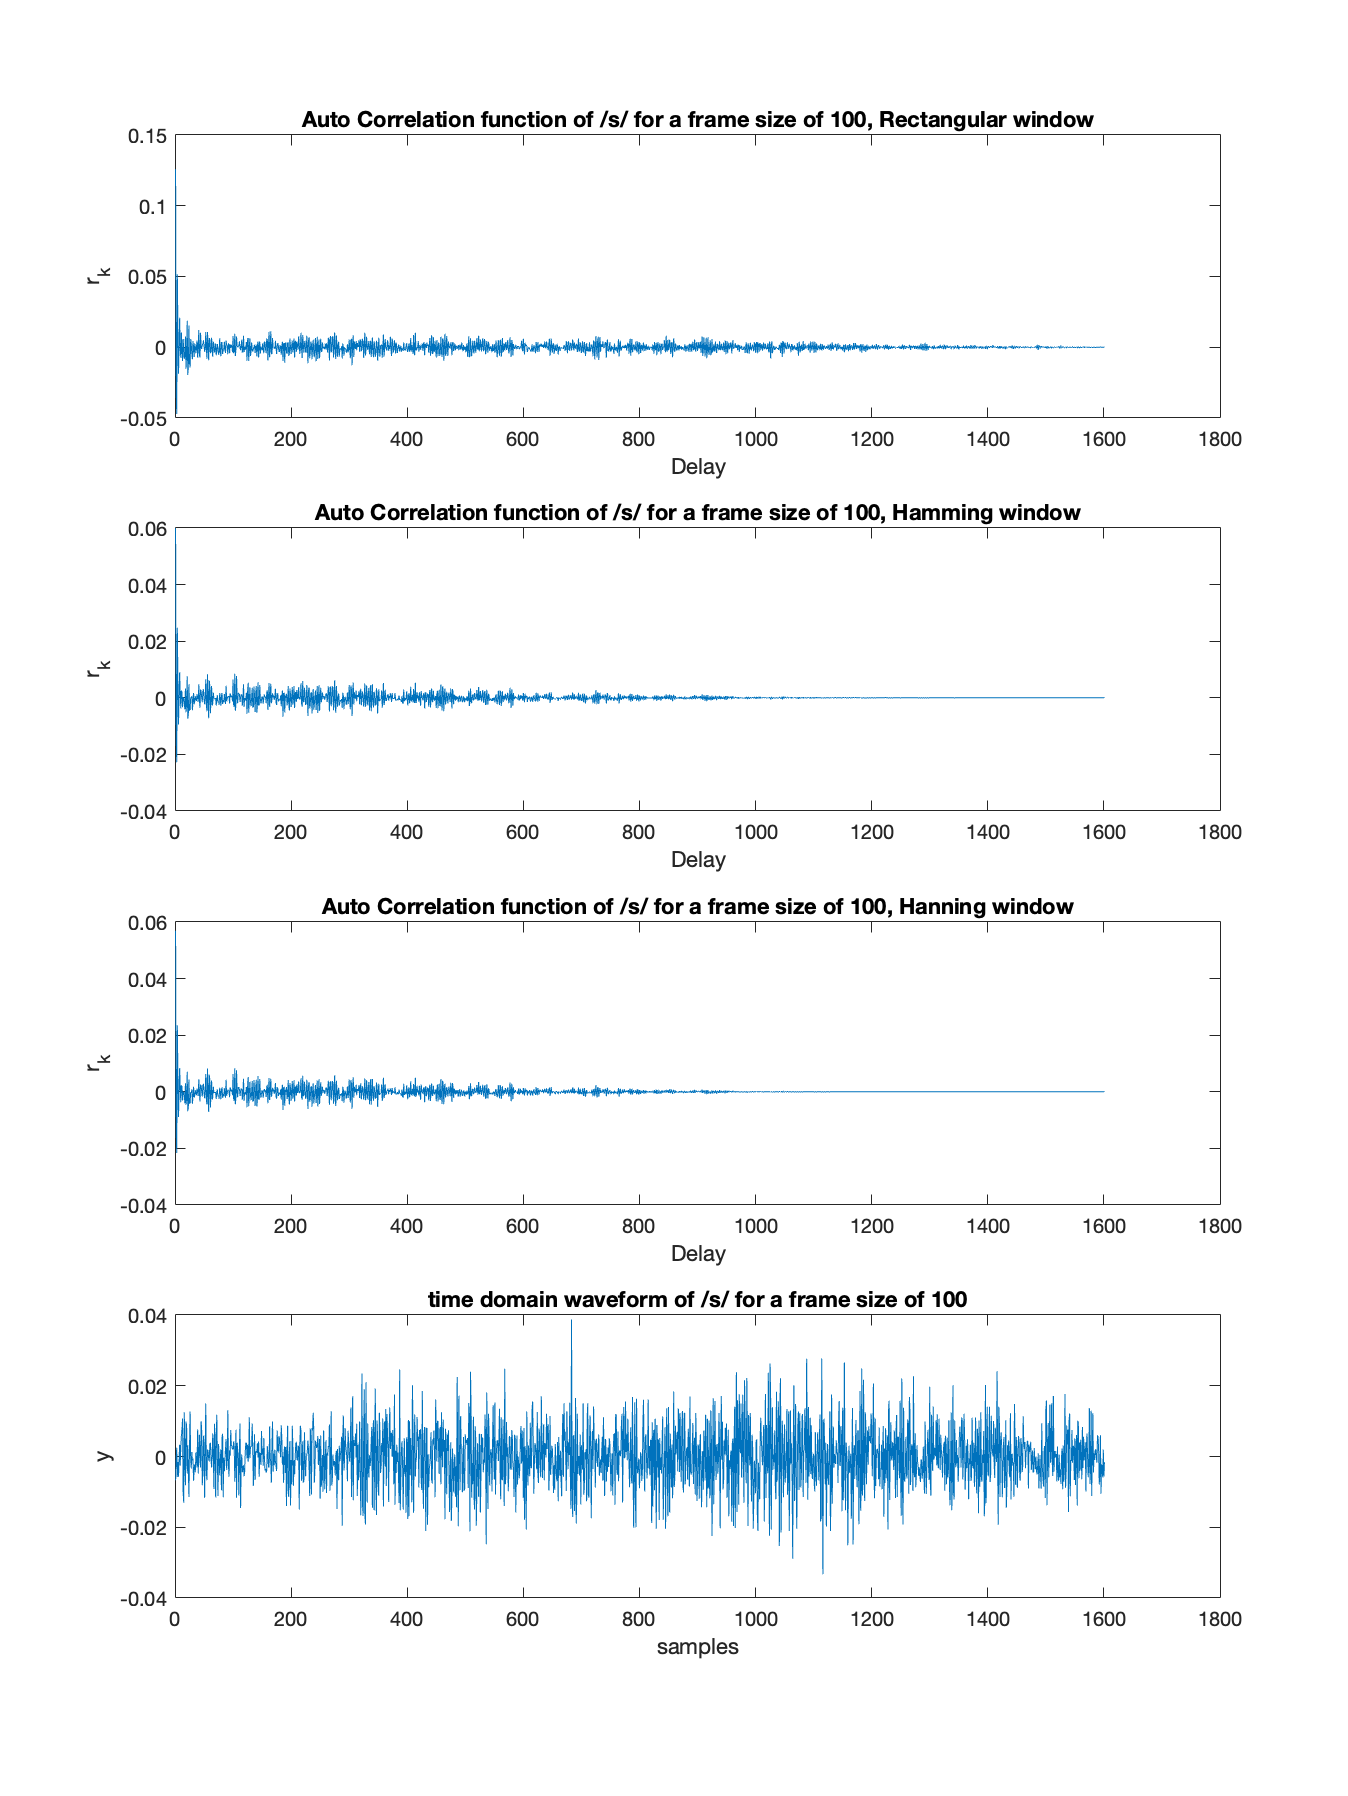

AutoCorrPlot(y_s100 , "/s/", "100");

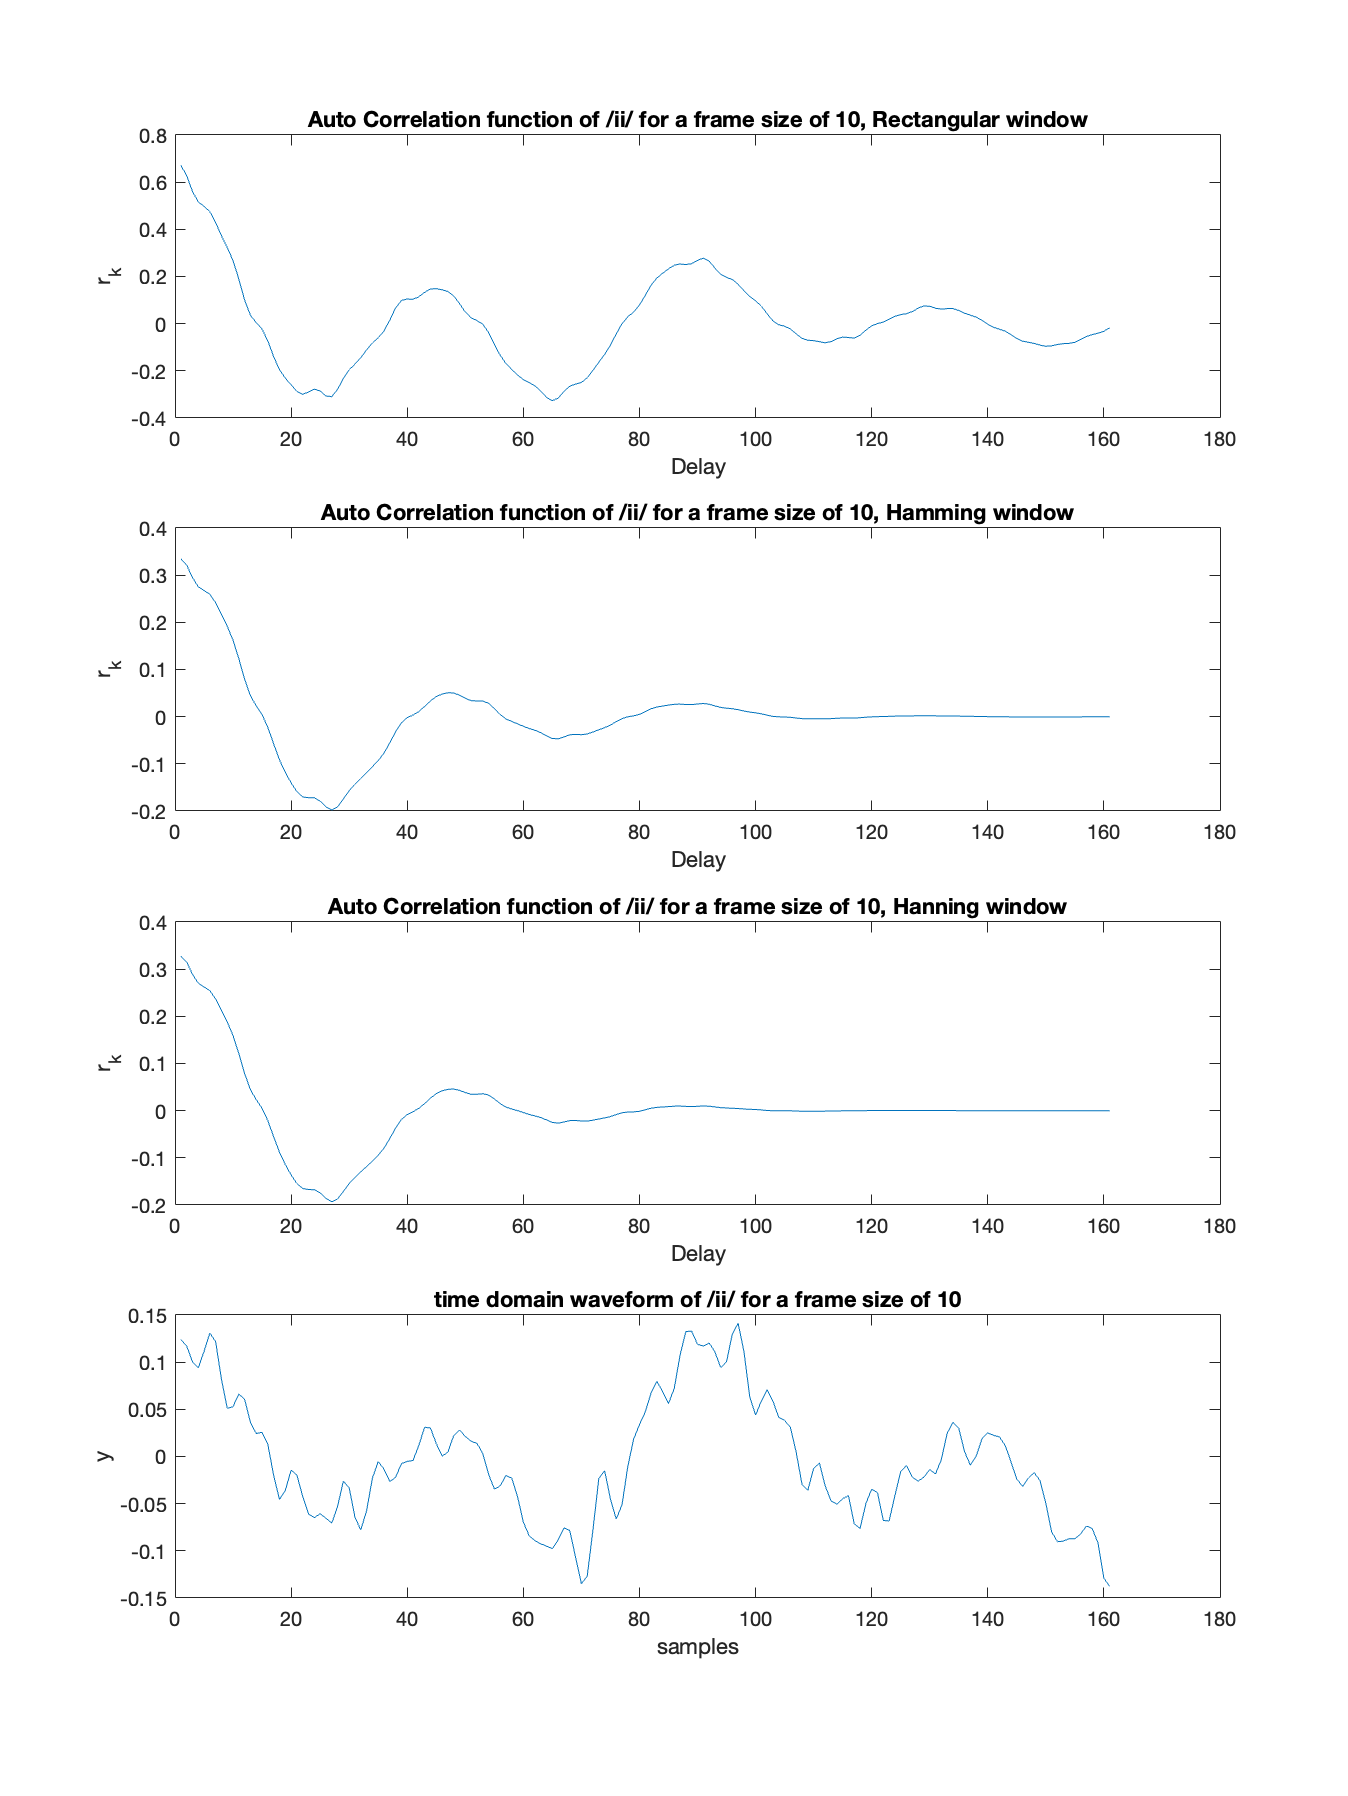

AutoCorrPlot(y_ii10 , "/ii/", "10");

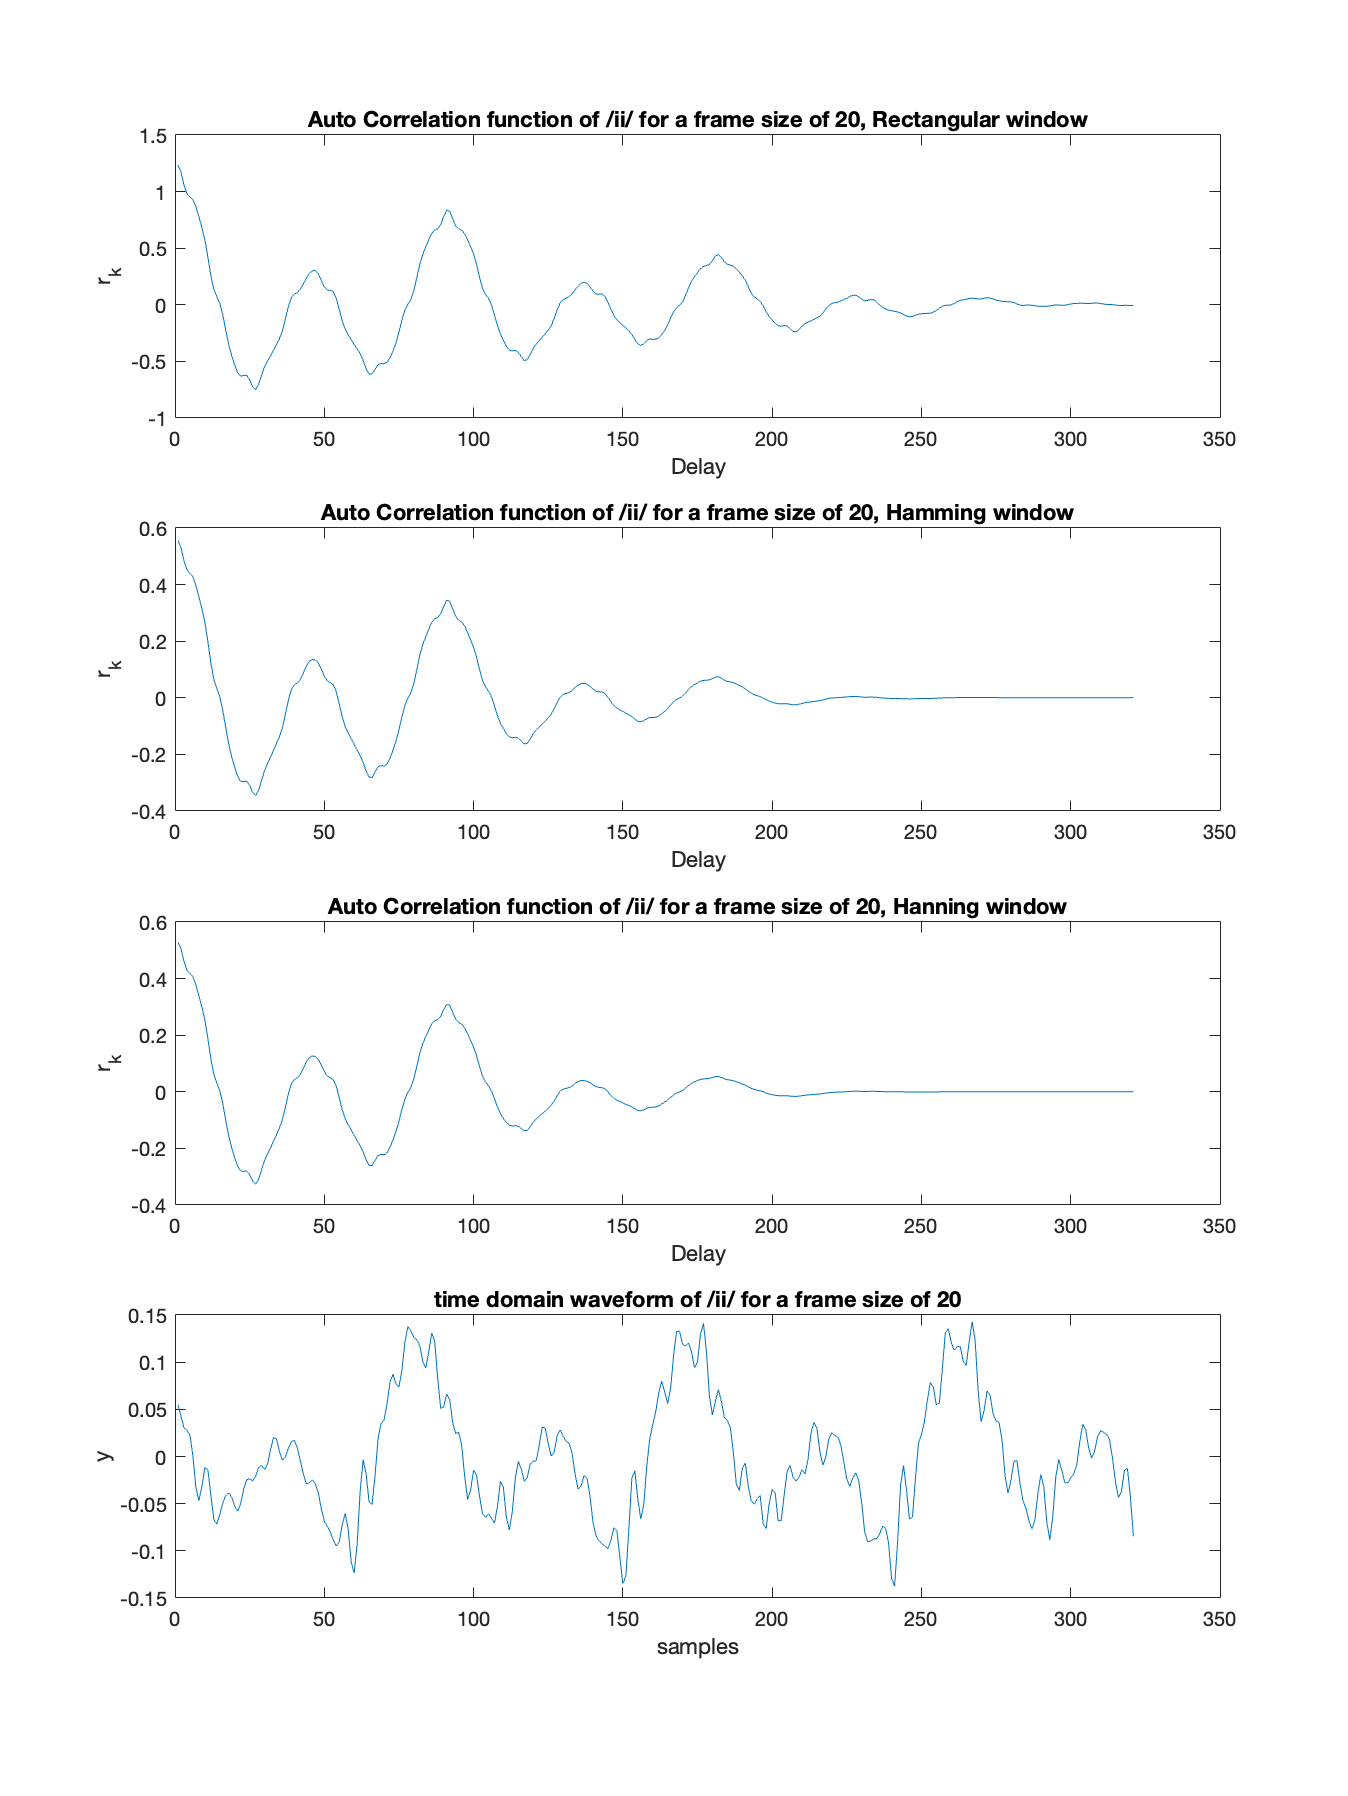

AutoCorrPlot(y_ii20 , "/ii/", "20");

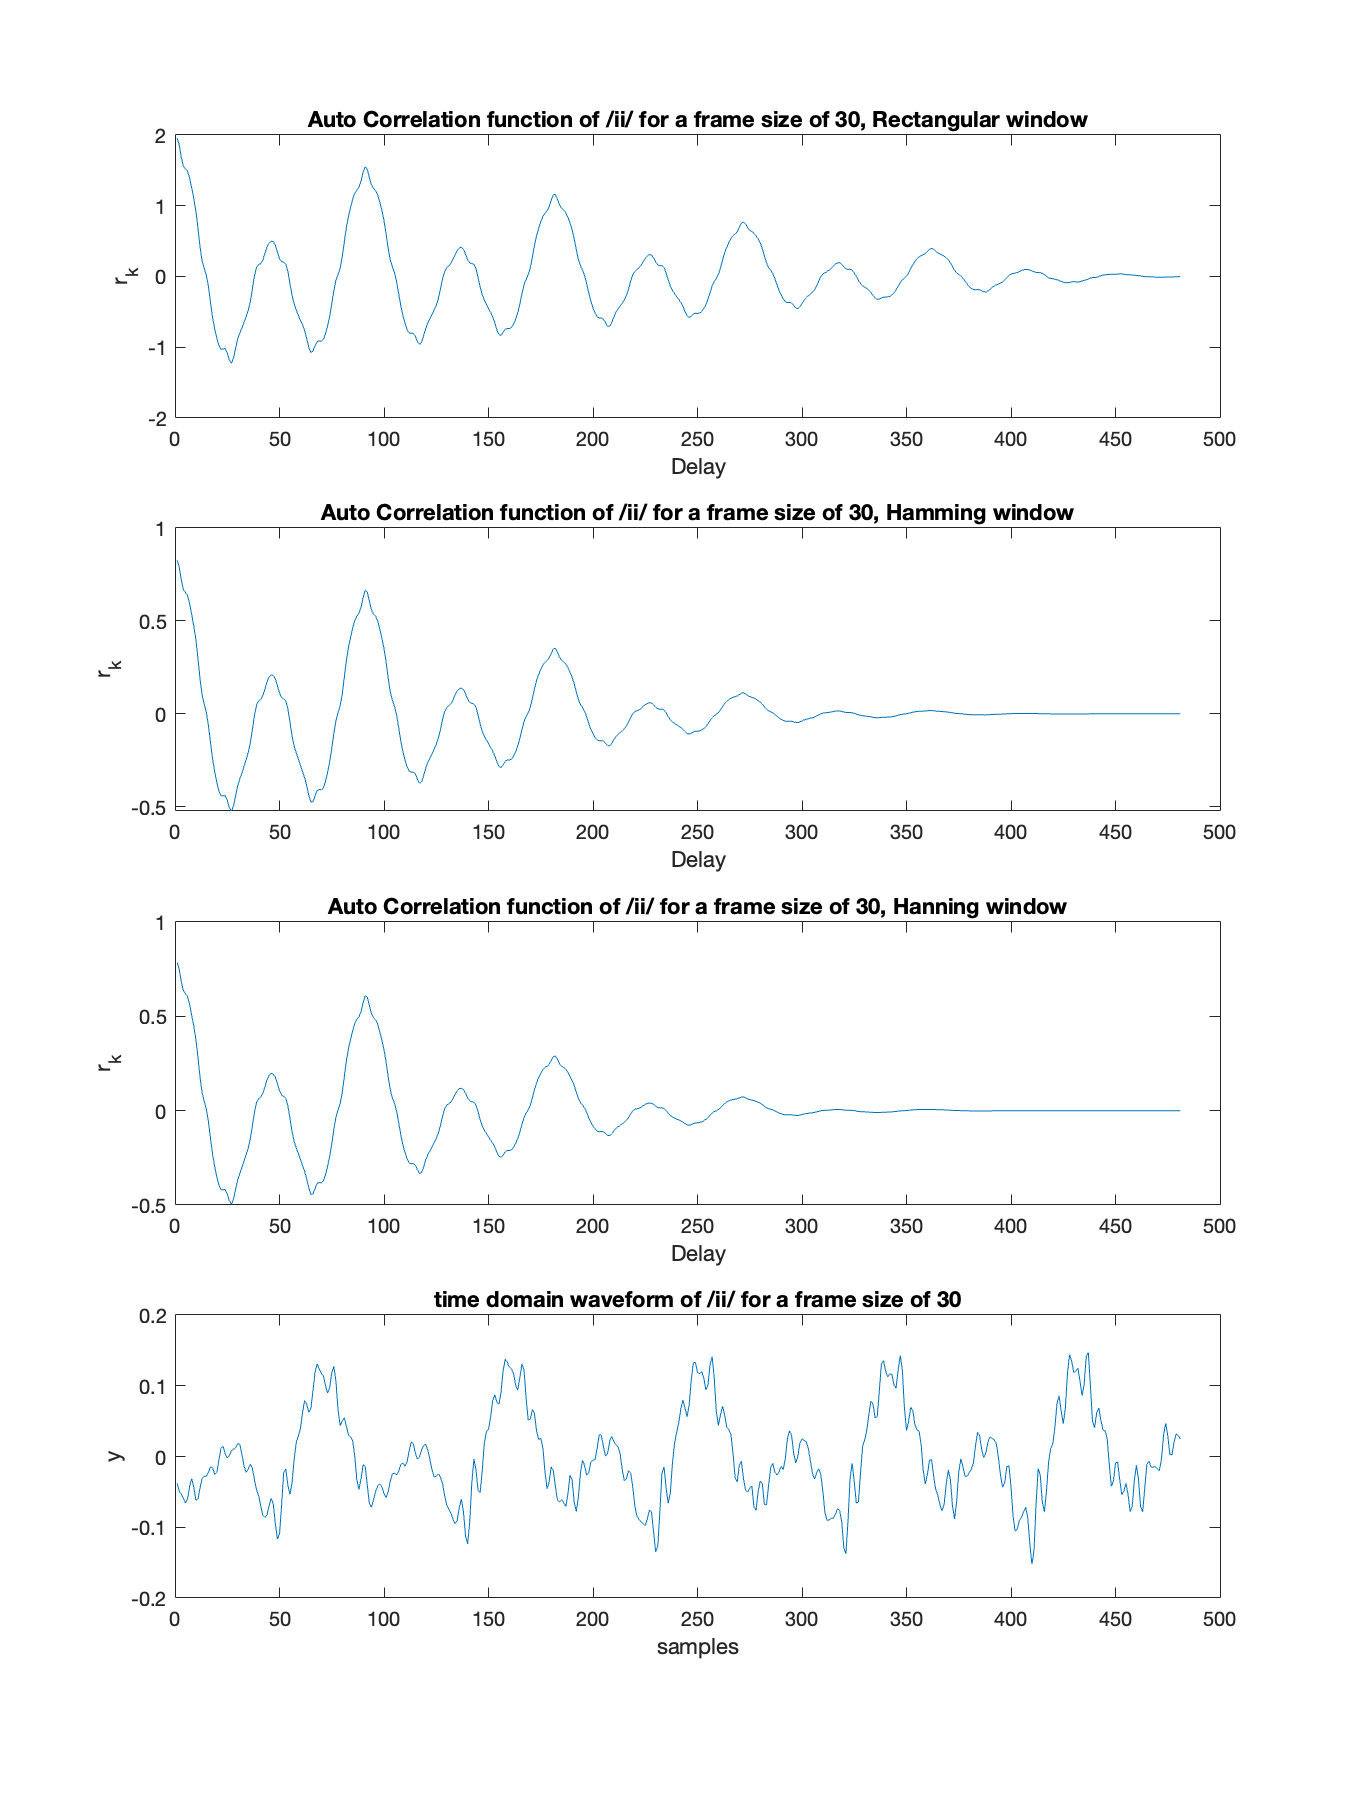

AutoCorrPlot(y_ii30 , "/ii/", "30");

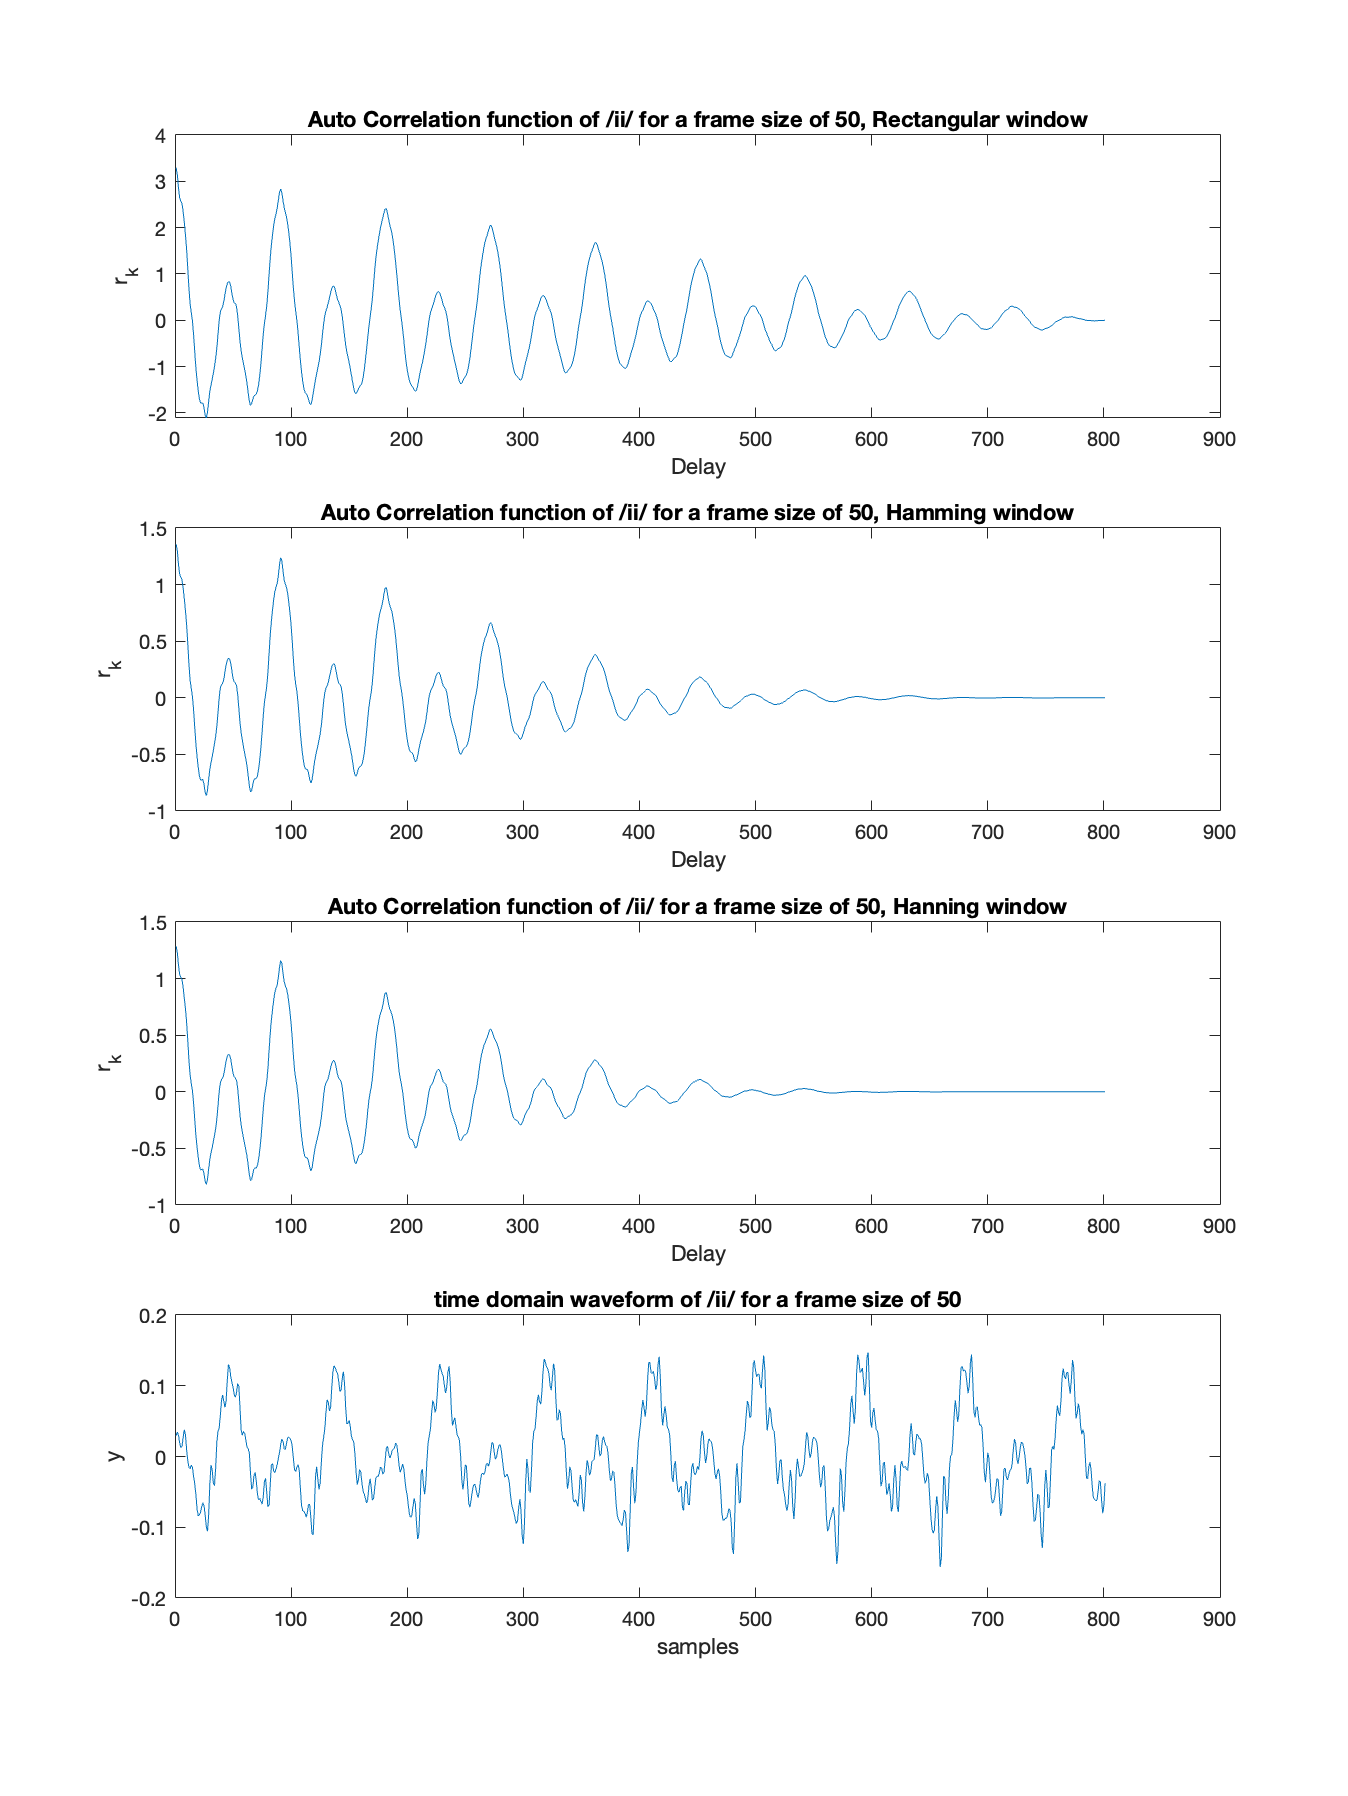

AutoCorrPlot(y_ii50 , "/ii/", "50");

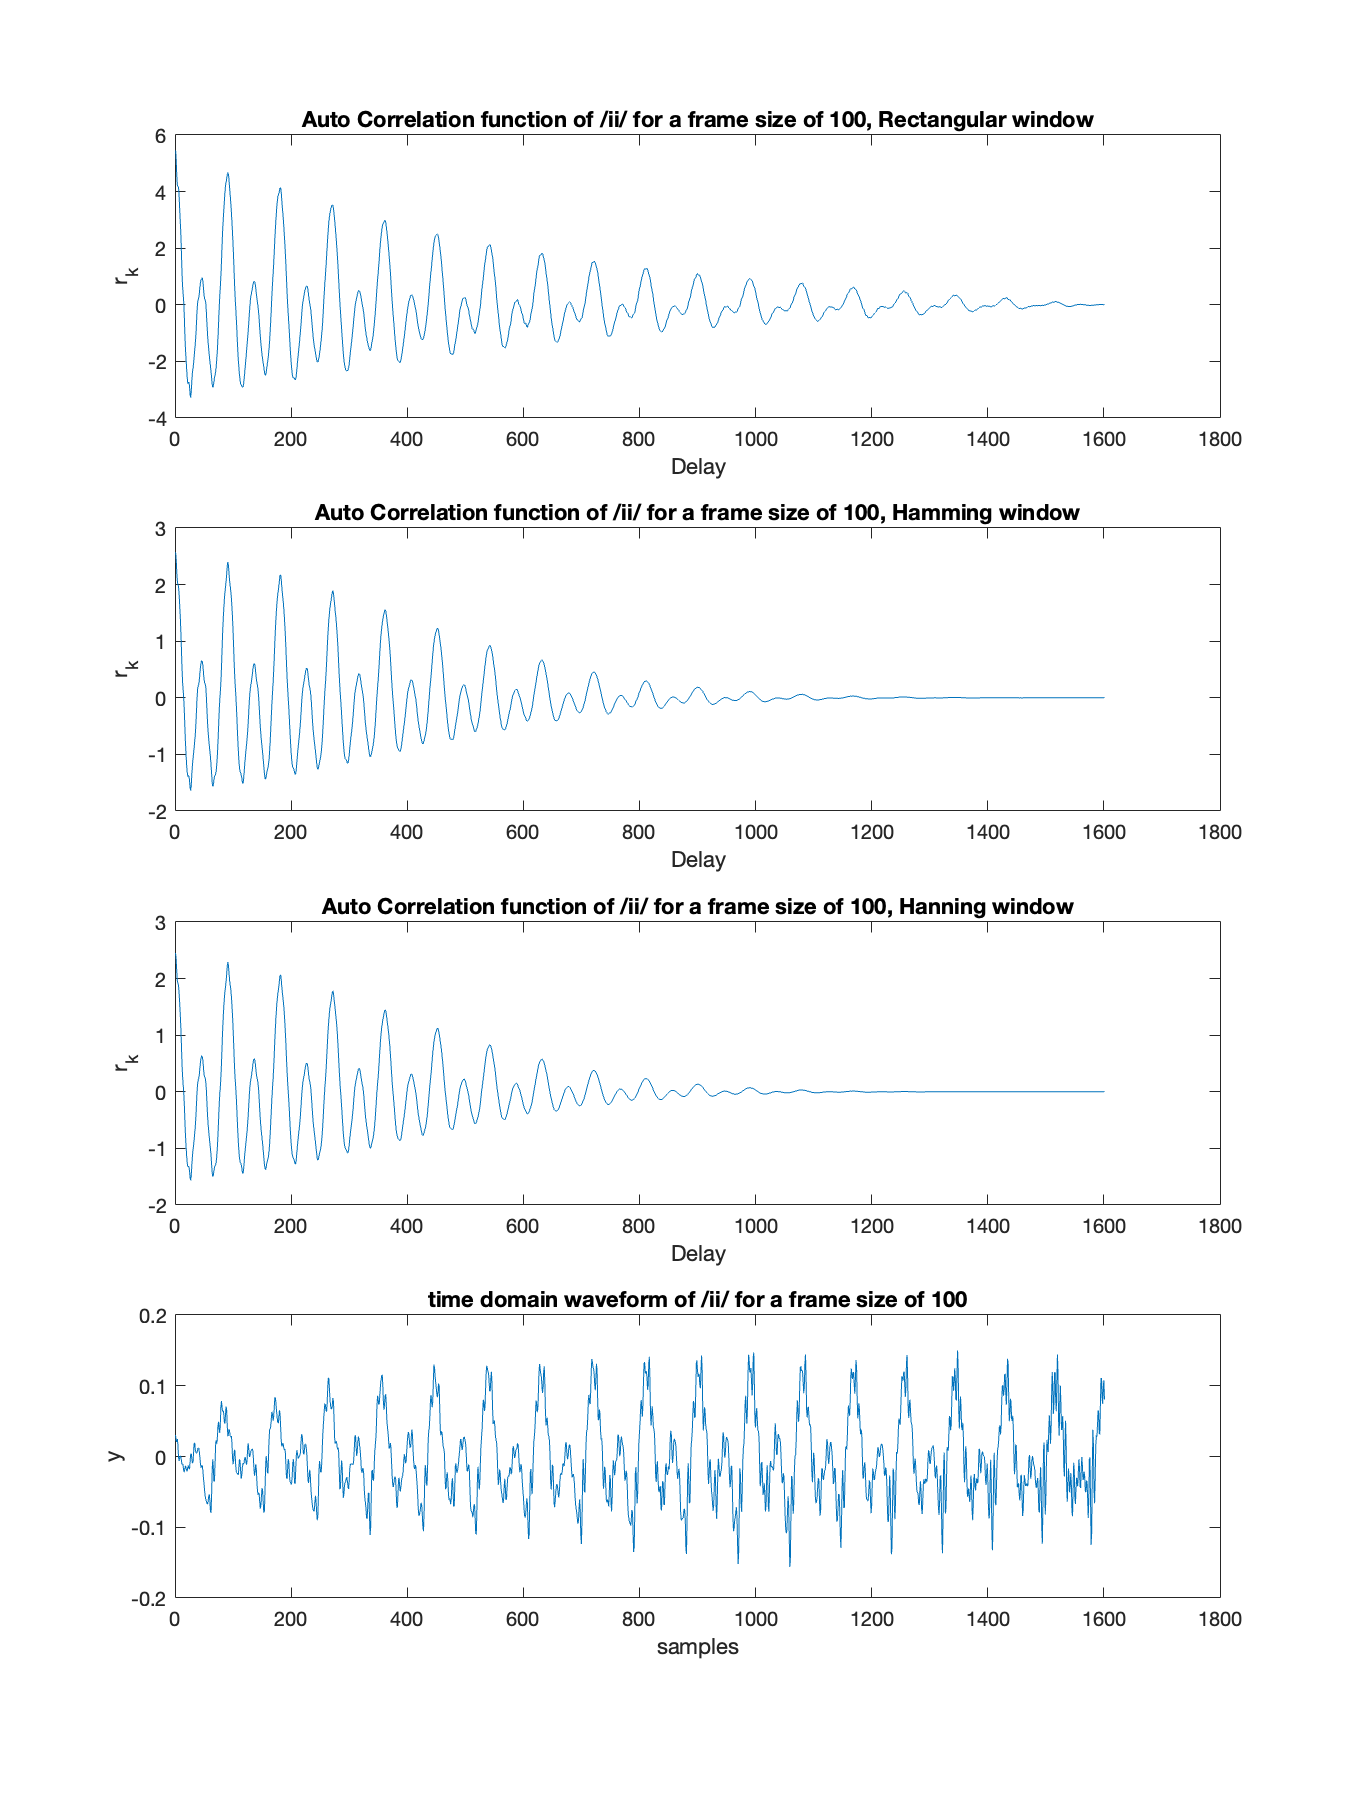

AutoCorrPlot(y_ii100 , "/ii/", "100");

**Observations:**

- We observe that the number of peaks in the auto correlation function of /ii/ increases as the frame size increase.

- The auto correlation function remains more or less constant for /s/ as we increase the frame size.

- When we apply a hamming  or hanning window to the speech segment the auto correlation function becomes zero for higher values of delay.

- There is not much of a difference in the auto correlation function obtained by using hamming window and hanning window.

**Inference:**

When we use a hamming or hanning window the edges of the signal get a lower values, at higher delays these lower values get correlated, hence the auto correlation function 

converges to zero for higher delays.

We should **select a window size of 20 - 50 ms** so as to preserve the quasi stationarity and getting multiple peaks at integer

multiple of the periods at the same time.

function autocorr = AutoCorrPlot(y , text1, text2)
    
    % Rectangular
    autocorr_r = AutoCorr(y);
    
    % Hamming
    autocorr_hm = AutoCorr(y.*hamming(length(y)));
    
    % Hanning
    autocorr_hn = AutoCorr(y.*hanning(length(y)));

    set(gcf,'Position',[2 2 1500 2000]);
    
    subplot(4,1,1);
    plot(autocorr_r);
    title("Auto Correlation function of "+ text1 +" for a frame size of " + text2 + ", Rectangular window");
    xlabel("Delay");
    ylabel("r_k");
    
    subplot(4,1,2);
    plot(autocorr_hm);
    title("Auto Correlation function of "+ text1 +" for a frame size of " + text2 + ", Hamming window");
    xlabel("Delay");
    ylabel("r_k");
    
    subplot(4,1,3);
    plot(autocorr_hn);
    title("Auto Correlation function of "+ text1 +" for a frame size of " + text2 + ", Hanning window");
    xlabel("Delay");
    ylabel("r_k");
    
    subplot(4,1,4);
    plot(y);
    title("time domain waveform of " + text1 +" for a frame size of " + text2);
    xlabel("samples");
    ylabel("y");
    
end


function autocorr = AutoCorr(y)

    autocorr = [];

    for shift = 0 : length(y) - 1
        
        buf = 0;
        
        for i = 1:length(y) - shift
           
            buf = buf + y(i)*y(i+shift);
            
        end
       
        autocorr = [autocorr buf];
        
    end
    
end

function zcr = ZCR(y,Fs, frameTime, frameRate, text)

    % Frame shift and frame size calculation
    frameSize = Fs*frameTime/1000;
    frameShift = Fs*frameRate/1000;

    %number of windows
    numWindows = floor((length(y) - frameSize)/frameShift) + 1;
    
    %Array to store zcr
    zcr = [];

    
    %iterating the windows
    for i = 1 : numWindows
        
        %determining the start and end of the given window
        winstart = 1 + frameShift*(i-1);
        
        winend = winstart + frameSize;
        
        %buffer varible
        buf = 0;
        
        %iterating from starting of window to end of window
        for j = winstart : winend - 1
            
            %incrementing if two consequtive elements have opposite sign
            if(y(j)*y(j+1) <= 0)
                buf = buf + 1;
            end
            
        end
        
        %division by frame size to compute rate
        buf = buf/frameSize;
        
        %appending calulated zcr for the current frame.
        zcr = [zcr buf];

    end
    
    %plotting
    plot(zcr);
    title("Zero Crossing Rate for frame size = " + text);
    xlabel("Frame Number");
    ylabel("ZCR");
    
end

function ste = STE(y,Fs, frameTime, frameRate, text)

    % Frame shift and frame size calculation
    frameSize = Fs*frameTime/1000;
    frameShift = Fs*frameRate/1000;

    %number of windows
    numWindows = floor((length(y) - frameSize)/frameShift) + 1;
    
    %Array to store zcr
    ste = [];

    
    %iterating the windows
    for i = 1 : numWindows
        
        %determining the start and end of a given window
        winstart = 1 + frameShift*(i-1);
        
        winend = winstart + frameSize;
        
        %buffer varible
        buf = 0;
        
        %iterating from starting of window to end of window
        for j = winstart : winend - 1
            
            buf = buf + y(j)*y(j);
            
        end
        
        %appending calulated ste for the current frame.
        ste = [ste buf];
        
    end
    
    %plotting
    plot(ste);
    title("Short Time Energy for frame size = " + text);
    xlabel("Frame Number");
    ylabel("Energy");
    
    
end